# Plots for PPT

clear all;
fig_folder = 'D:\Storage\SchoolWork\BU\ME701_Spring2020\ME701_project\figures\ppt';

## Search for We and Wu to give optimal setteling time

% We_Wu_grid = load('dataLogging_We_Wu_grid.mat');
% % score(plant_number,We,Wu)
% fid(1)=plot_cutoff_search(We_Wu_grid.score_l_h(1,:,:),...
%     'x_array',We_Wu_grid.We_array,'x_label','We',...
%     'y_array',We_Wu_grid.Wu_array,'y_label','Wu',...
%     'z_label','SettleTime');

## Plot Step Responces

### load data

plants = load('plants.mat');
controllers = load('Controllers.mat');

plant_names = {'plant_aug','plant_aug','plant_aug','plant_CL_LQR',...
          'plant_CL_LQR','plant_CL_LQR','plant_aug','plant_aug'};
plant_names_u = strcat(plant_names,'_u')

plant_names_u = 1×8 cell array
    {'plant_aug_u'}    {'plant_aug_u'}    {'plant_aug_u'}    {'plant_CL_LQR_u'}    {'plant_CL_LQR_u'}    {'plant_CL_LQR_u'}    {'plant_aug_u'}    {'plant_aug_u'}


controller_names = {'controller_none','controller_H2','controller_Hinf','controller_cascade',...
                'controller_cascade_H2','controller_cascade_LQG','controller_LQR','controller_LQG'};
titles_names = {'None','H_2','H_\infty','Cascade LQR H_\infty',...
          'Cascade H_2','Cascade LQG H_\infty','LQR','LQG'};
feedback_names = [1,1,1,1,1,1,-1,1];

### With Perfect Plant

runs = [7,3,4]

runs =      7     3     4


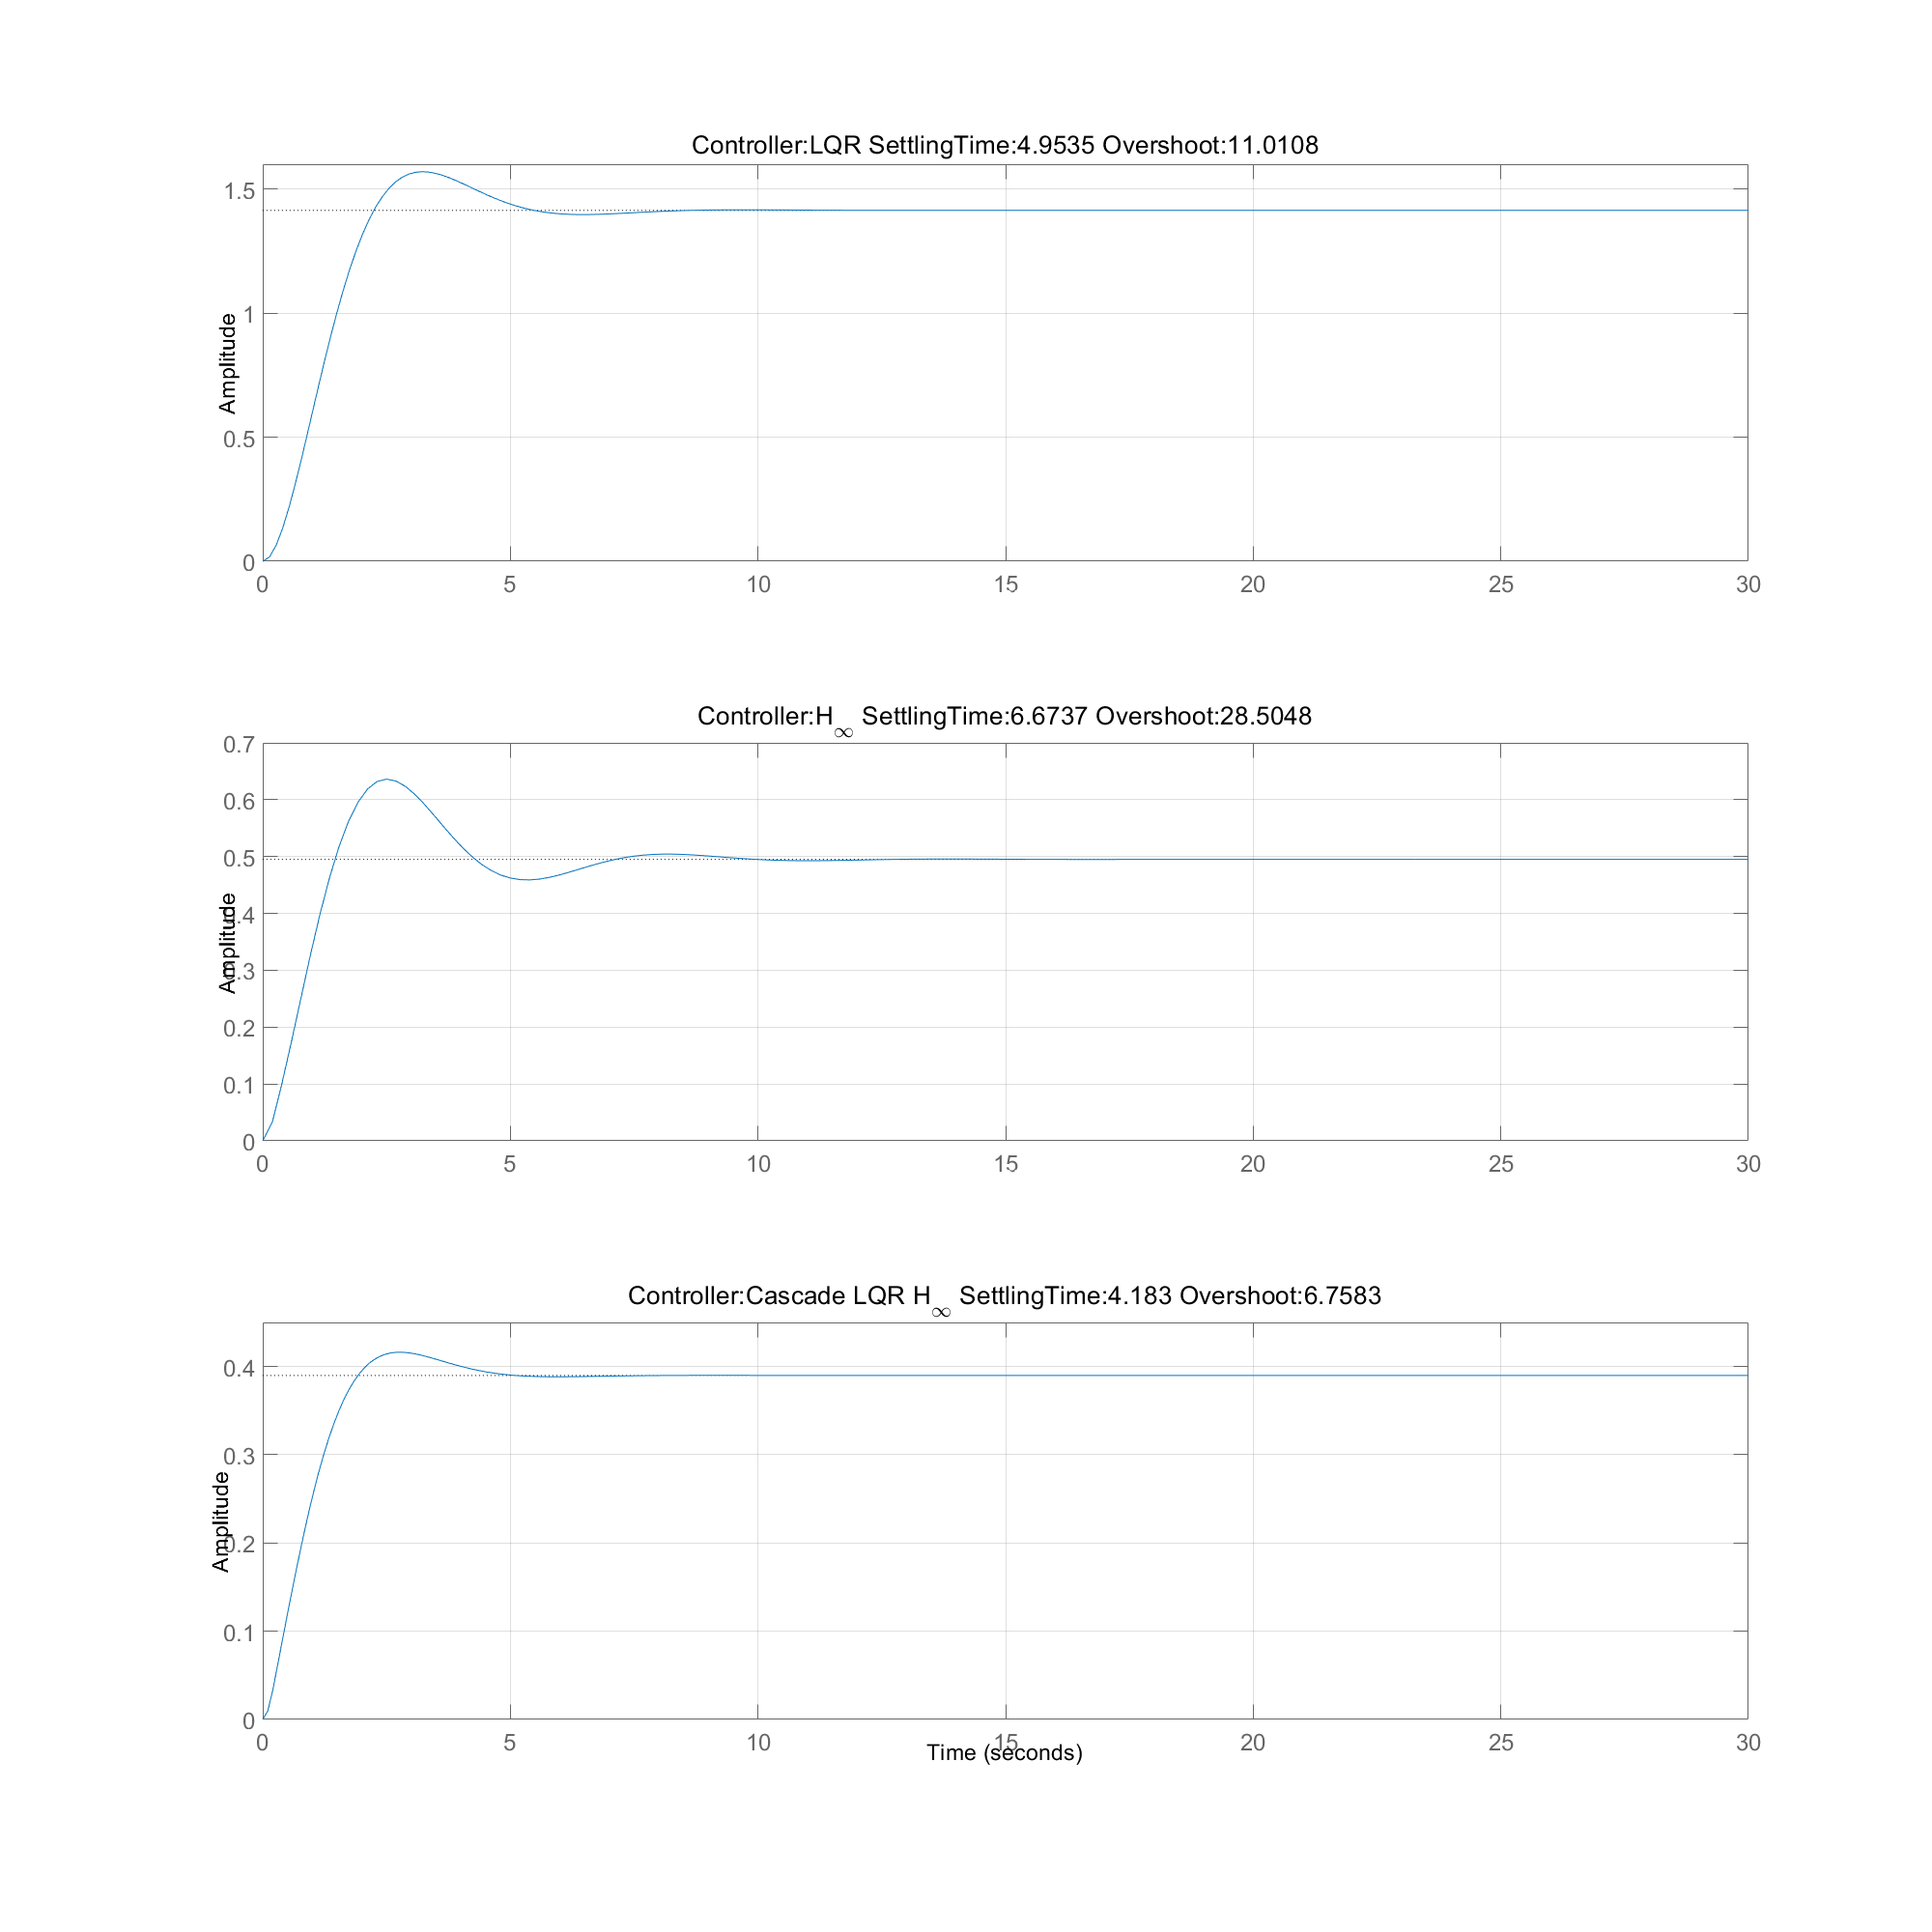

fid(1)=plot_step_responce(controllers,plants,...
    'plant',plant_names(runs),...
    'controller',controller_names(runs),...
    'feedback',feedback_names(runs),...
    'title',titles_names(runs),...
    'FigureTitle','ppt_plot_stepResponce_A');


runs = [1,7,8,2]

runs =      1     7     8     2


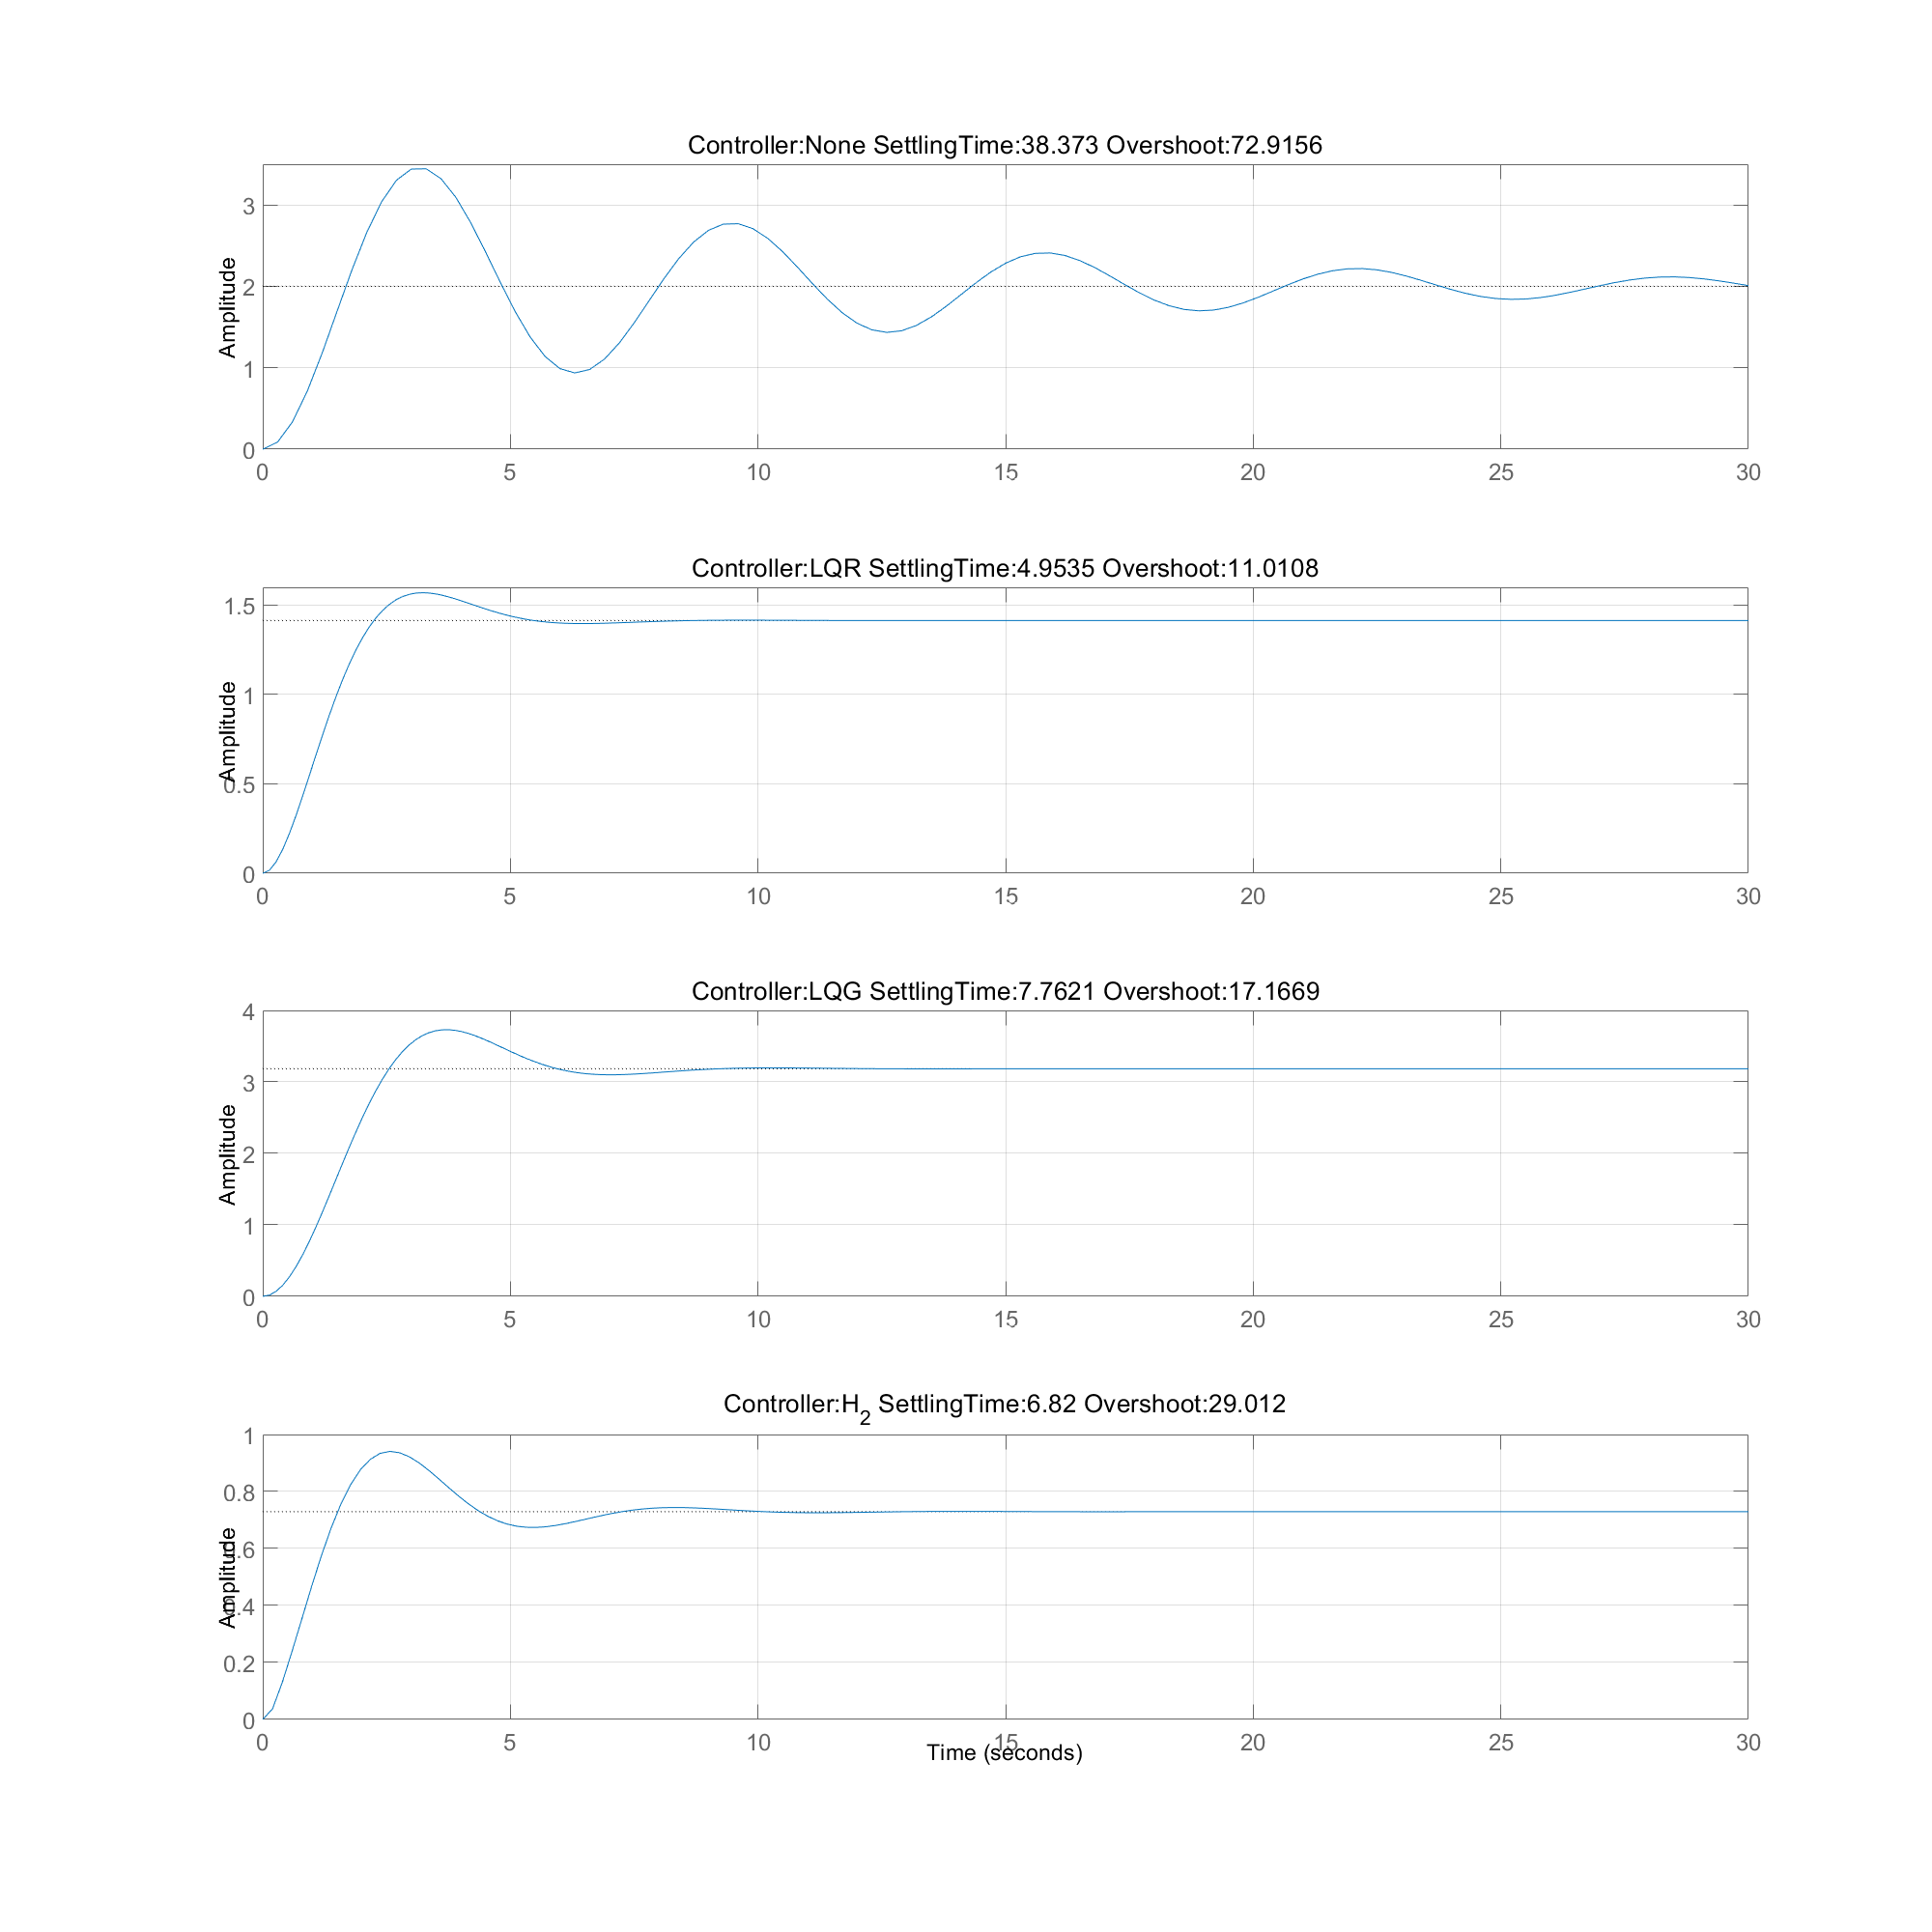

fid(2)=plot_step_responce(controllers,plants,...
    'plant',plant_names(runs),...
    'controller',controller_names(runs),...
    'feedback',feedback_names(runs),...
    'title',titles_names(runs),...
    'FigureTitle','ppt_plot_stepResponce_B');


runs = [3,4,5,6]

runs =      3     4     5     6


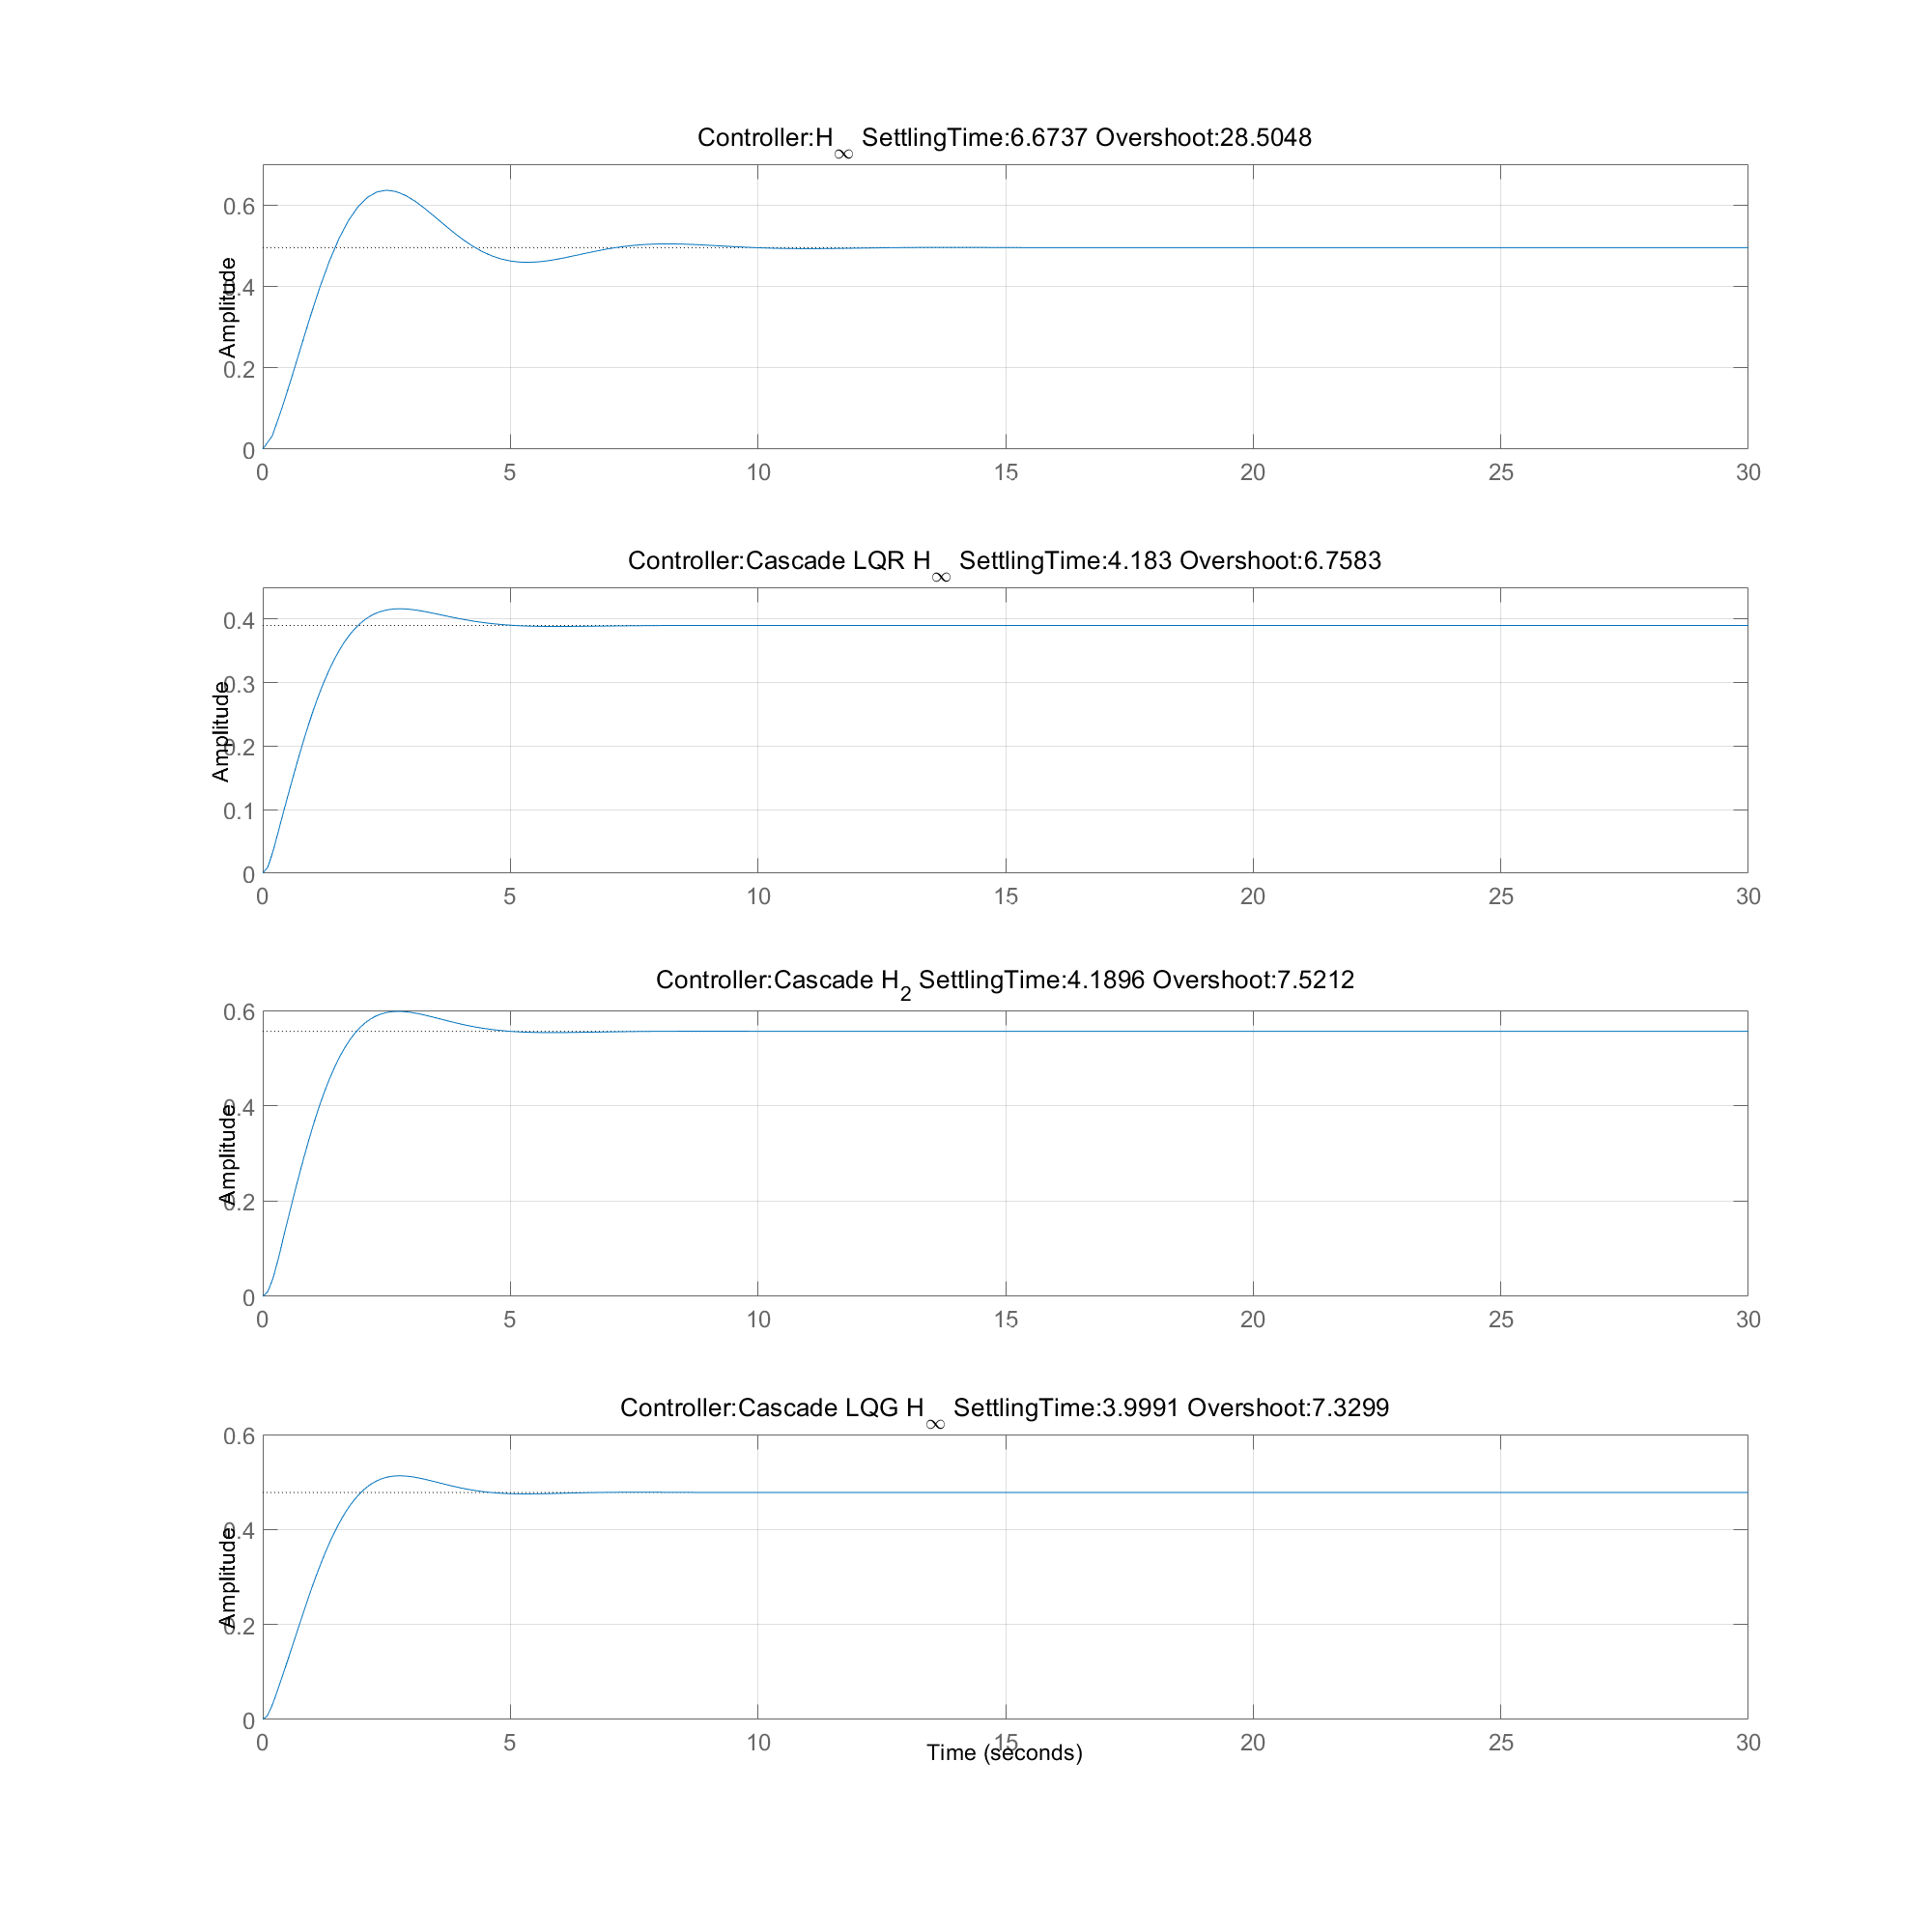

fid(3)=plot_step_responce(controllers,plants,...
    'plant',plant_names(runs),...
    'controller',controller_names(runs),...
    'feedback',feedback_names(runs),...
    'title',titles_names(runs),...
    'FigureTitle','ppt_plot_stepResponce_C');

### With Plant Errors

runs = [1:8]

runs =      1     2     3     4     5     6     7     8


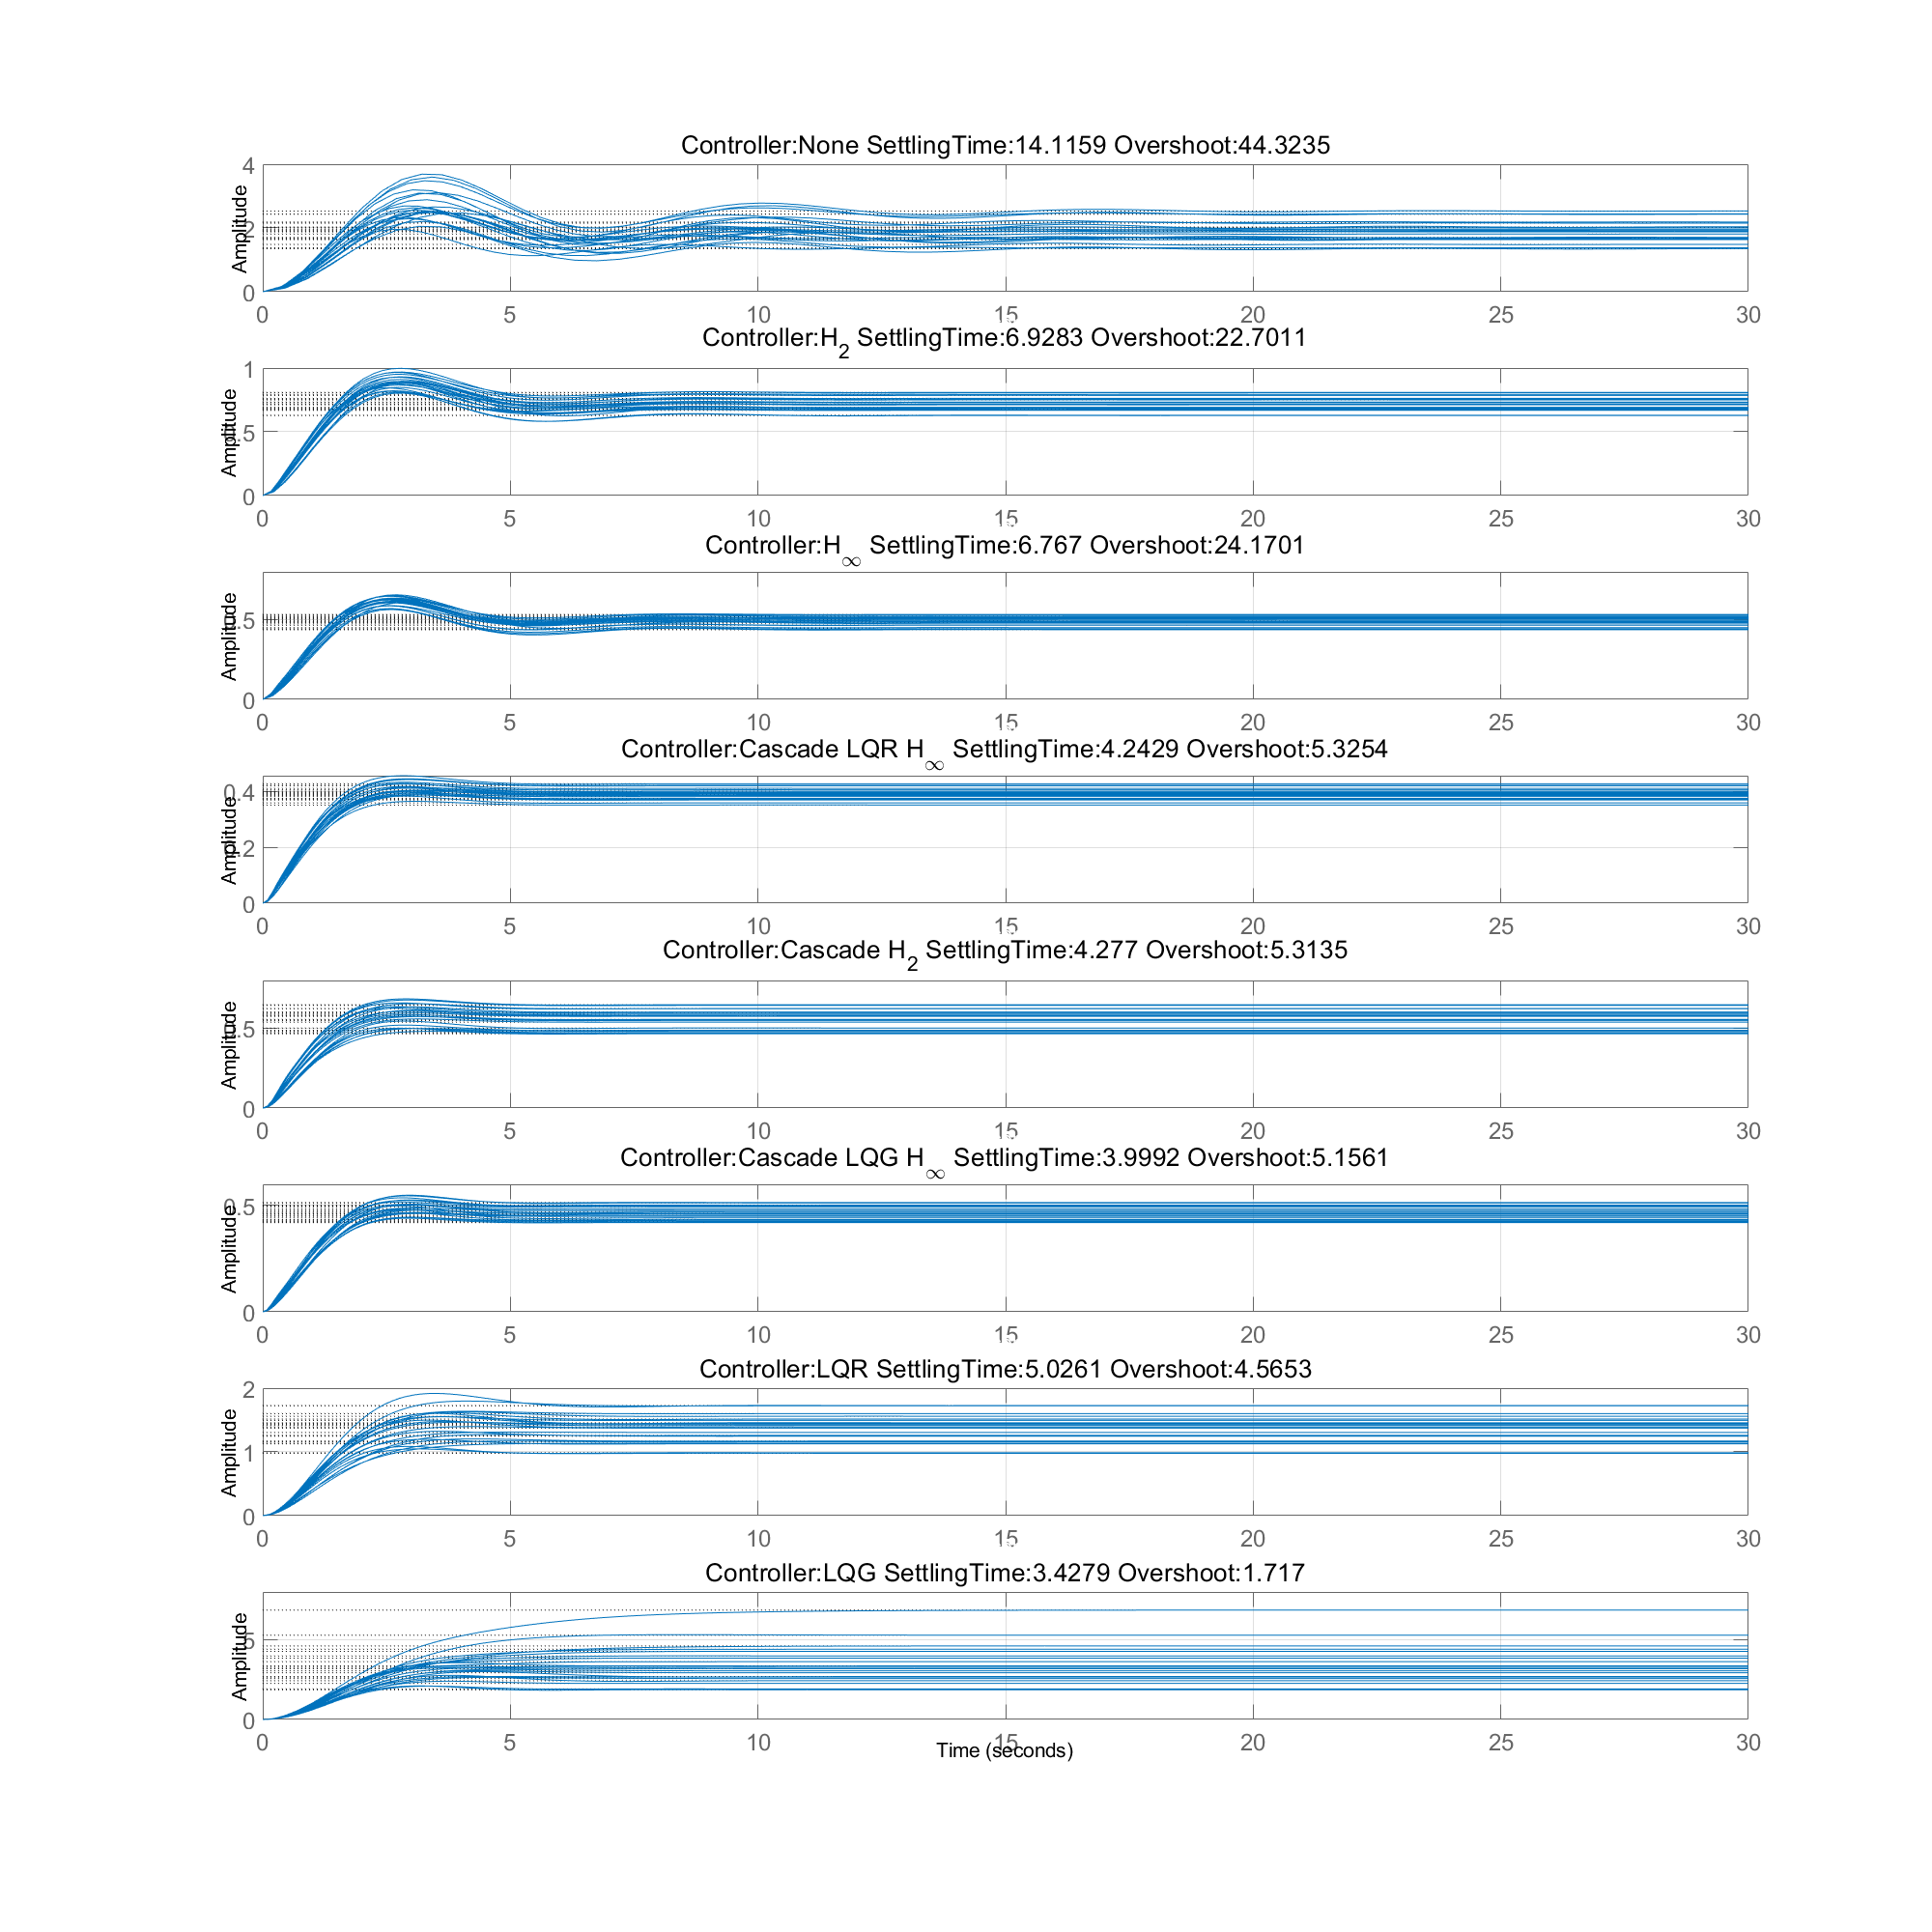

fid(4)=plot_step_responce(controllers,plants,...
    'plant',plant_names_u(runs),...
    'controller',controller_names(runs),...
    'feedback',feedback_names(runs),...
    'title',titles_names(runs),...
    'FigureTitle','ppt_plot_stepResponce_uncertaity');

## Table of phase margin's

% runs = [1:8]
% table_of_phase_margin(controllers,plants,...
%     'plant',plant_names(runs),...
%     'controller',controller_names(runs),...
%     'feedback',feedback_names(runs),...
%     'title',titles_names(runs),...
%     'FigureTitle','PhaseMargin')

## Plot from simulink results

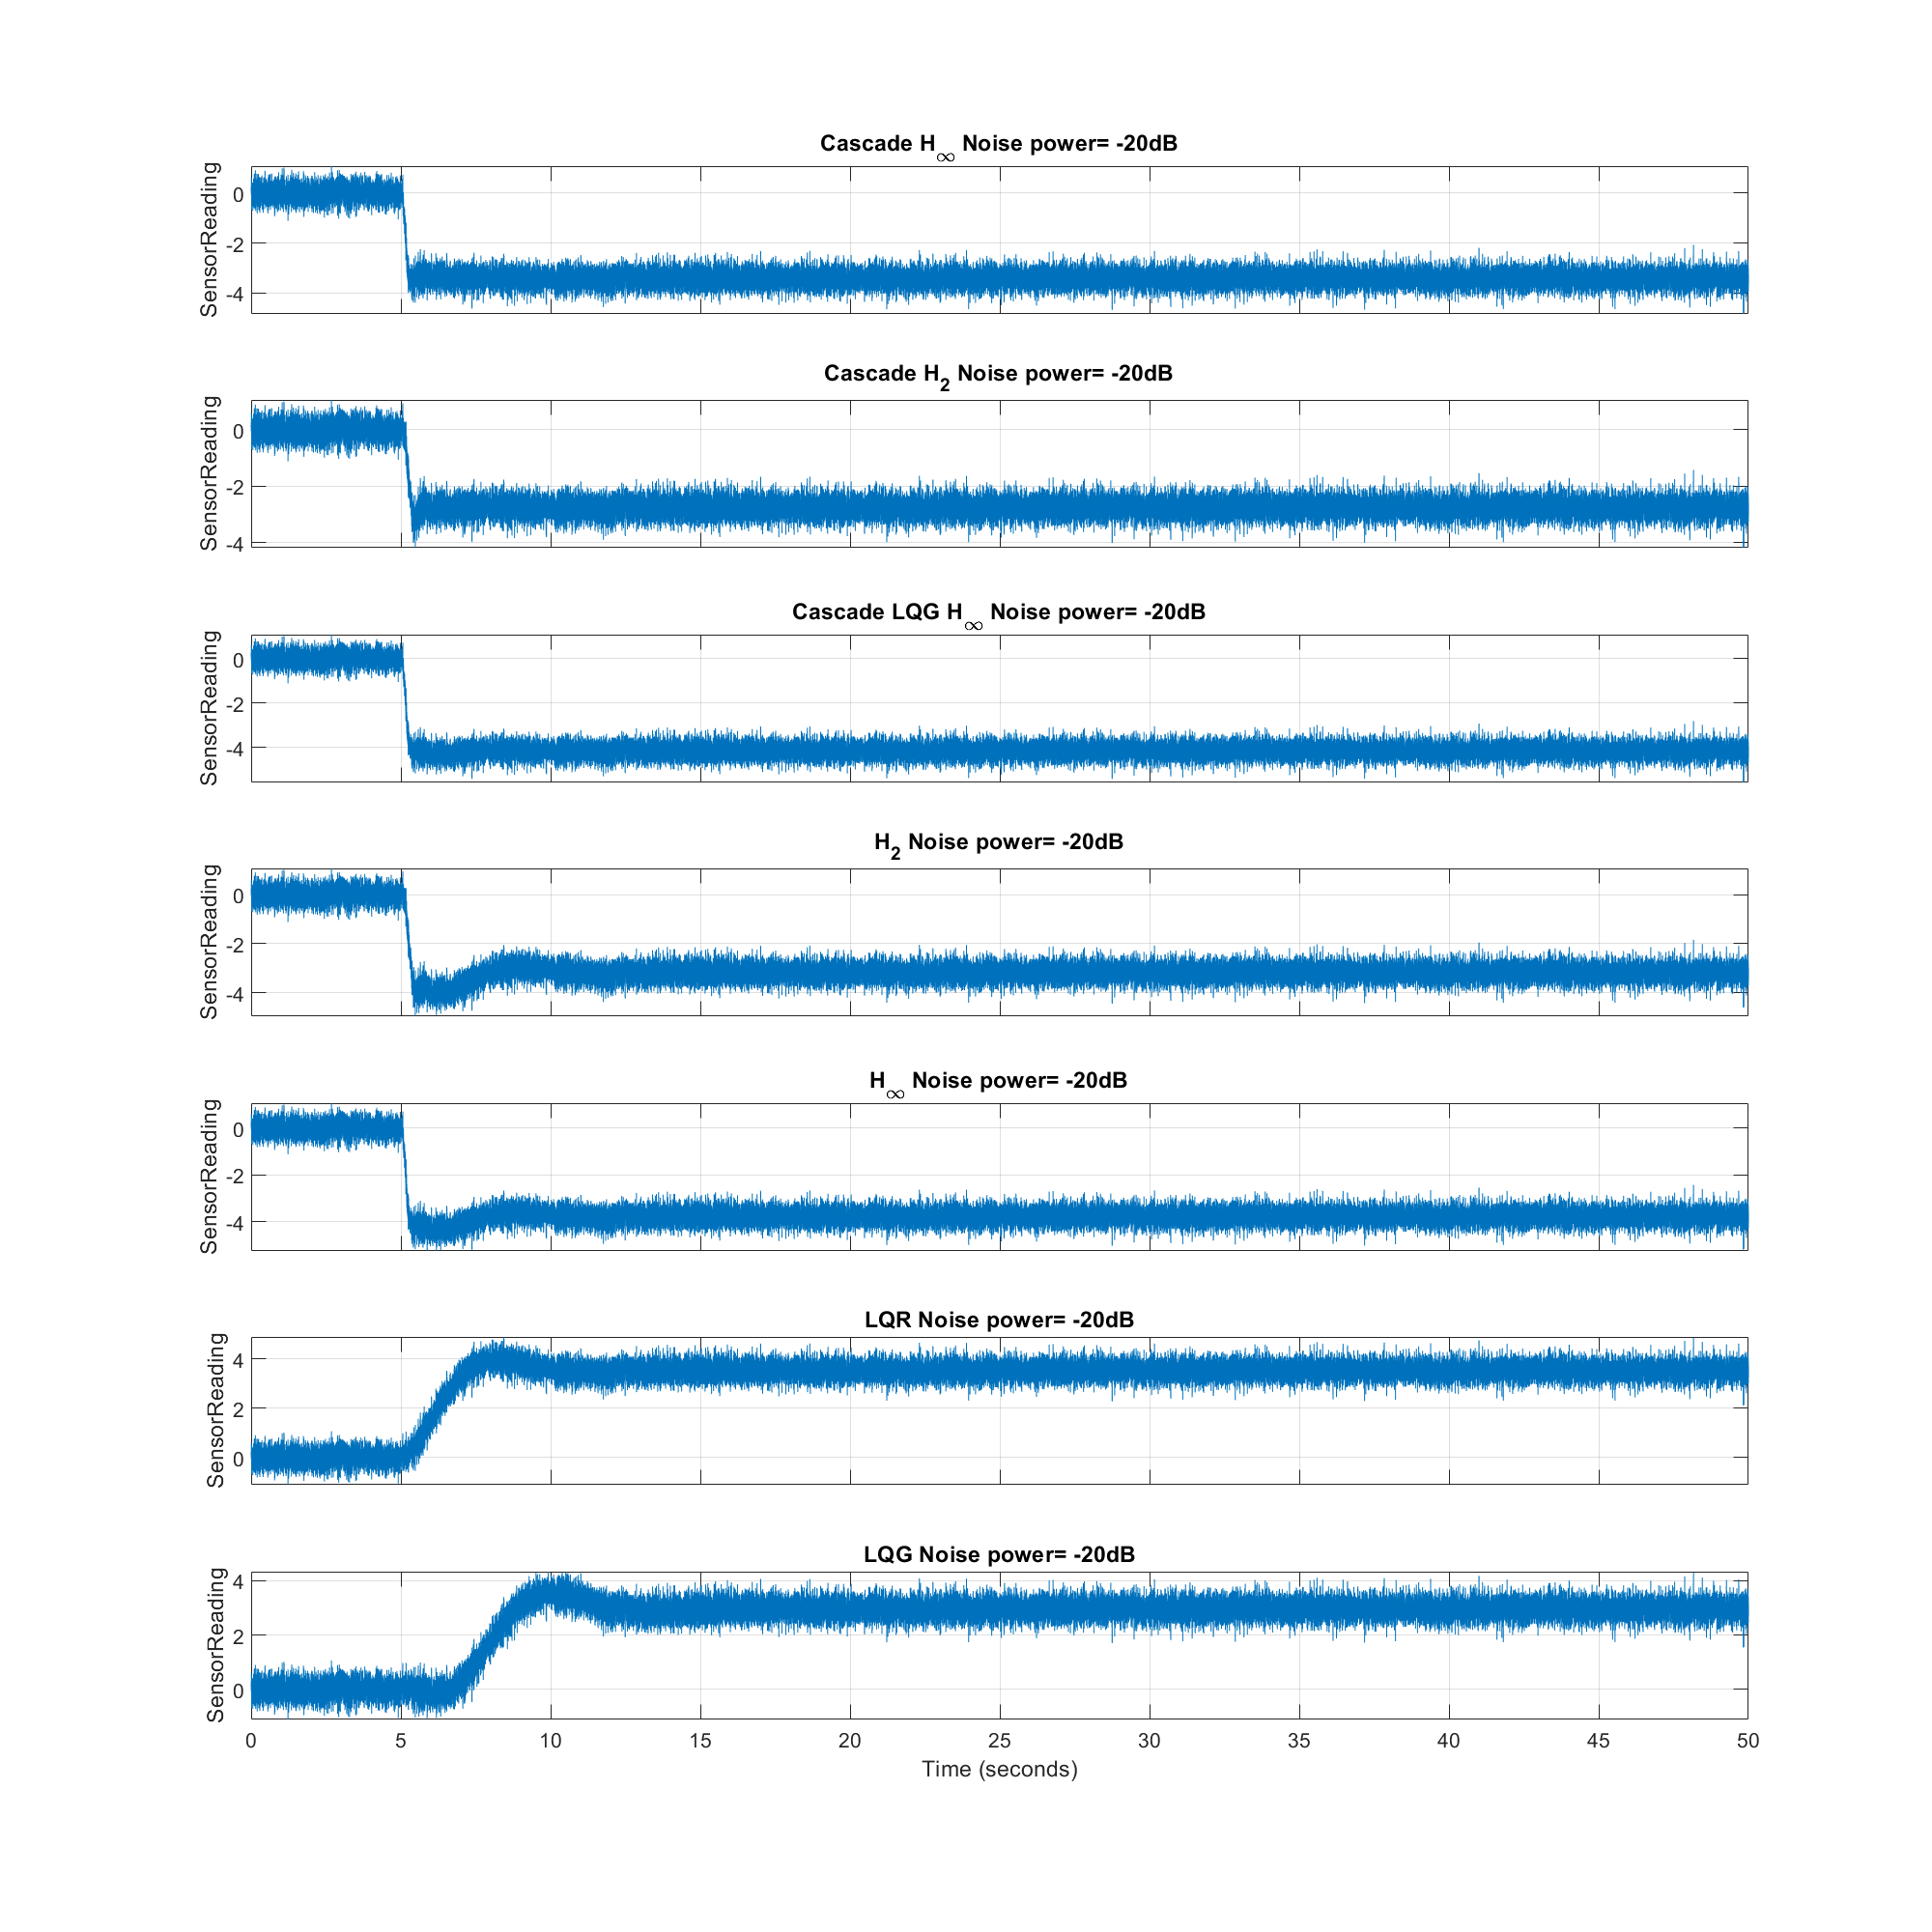

load('sim_results.mat');
runs = [2:8];
keys_names = {'None','Cascade_Hinf_LQR','H2_LQR','Hinf_LQG','H2','Hinf','LQR','LQG'};
titles_names = {'None','Cascade H_\infty','Cascade H_2','Cascade LQG H_\infty','H_2','H_\infty','LQR','LQG'};
fid(5)=plot_map(results(1).Use_Noise,'keys',keys_names(runs),'title',strcat(titles_names(runs),' Noise power= -20dB'),'FigureTitle','ppt_plot_stepResponce_noise');

%fid(6)=plot_map(results(1).Dont_Use_Noise,'keys',keys_names(runs),'title',strcat(titles_names(runs),' Noise power= -\infty dB'),'FigureTitle','CascadeResponceTrue');


## Plot Misalignments

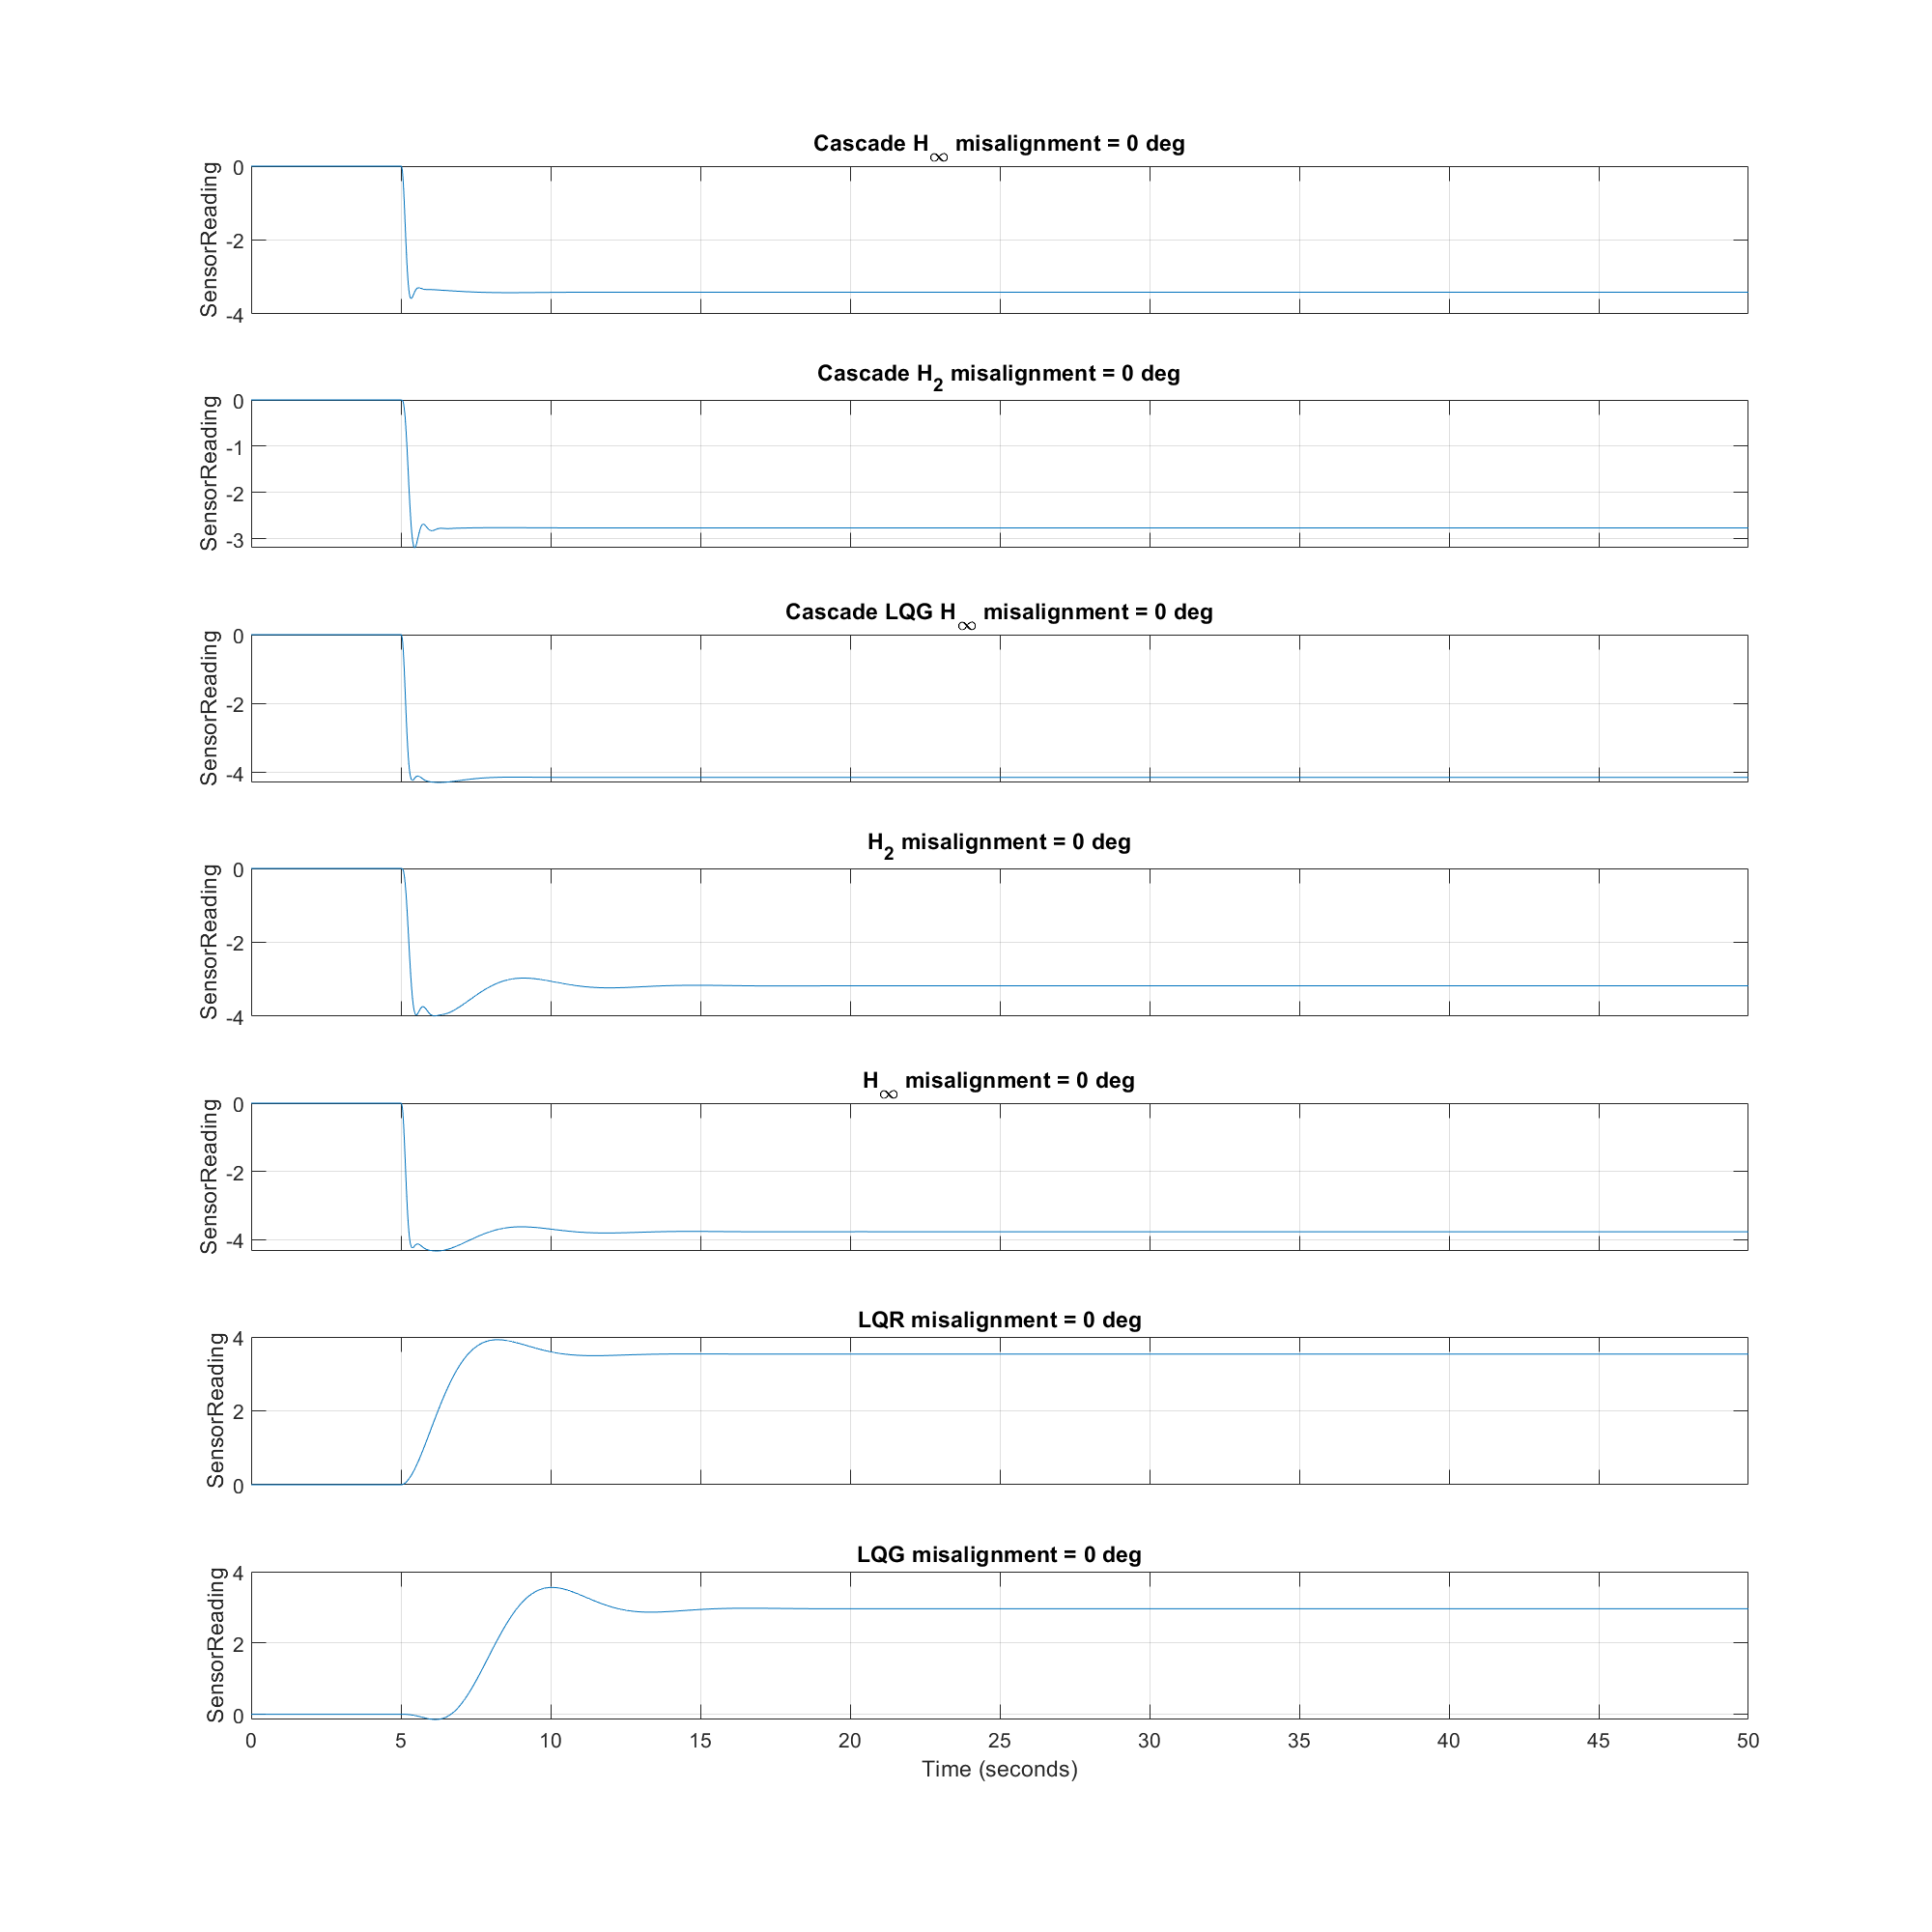

fid(6)=plot_map(results(1).Dont_Use_Noise,'keys',keys_names(runs),'title',strcat(titles_names(runs),' misalignment = 0 deg'),'FigureTitle','ppt_plot_misaligned_0');

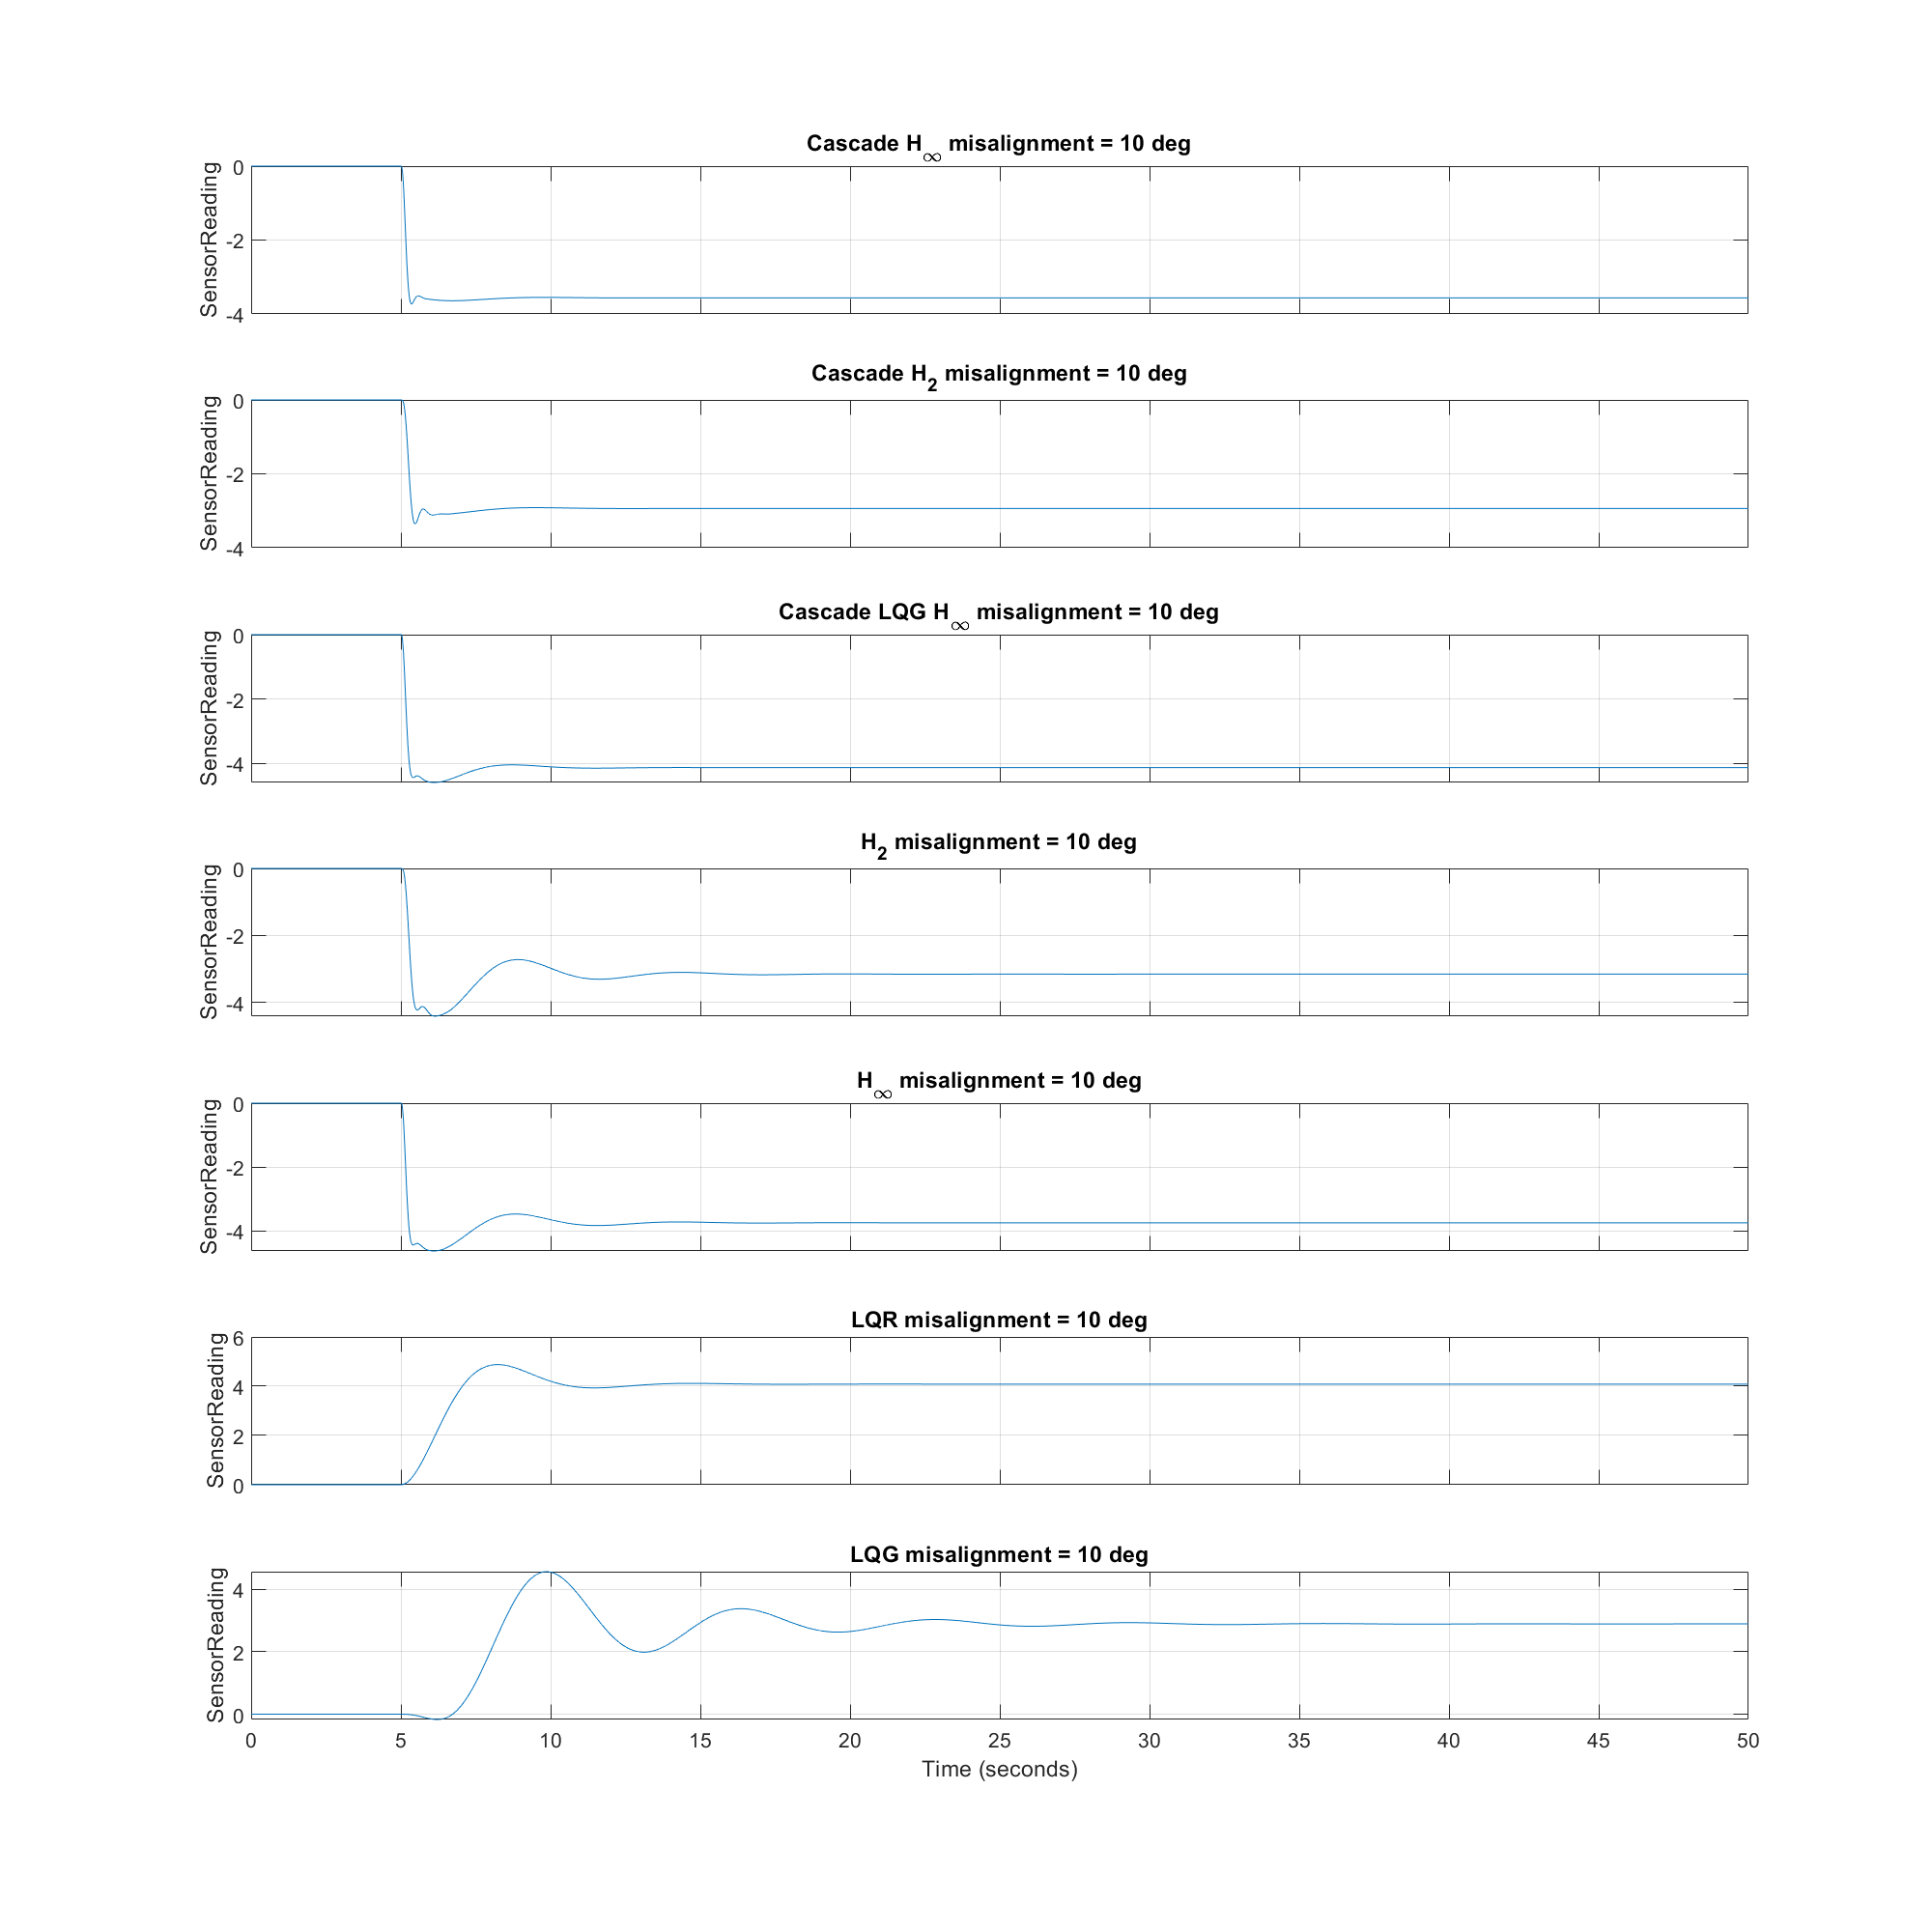

fid(7)=plot_map(results(5).Dont_Use_Noise,'keys',keys_names(runs),'title',strcat(titles_names(runs),' misalignment = 10 deg'),'FigureTitle','ppt_plot_misaligned_10');


% fid(1)=plot_misalignment({results.Use_Noise},...
%     'keys','LQG',...
%     'title','LQG',...
%     'FigureTitle','Misaligment_LQG',...
%     'misalignment',misalighments);


## Cascade

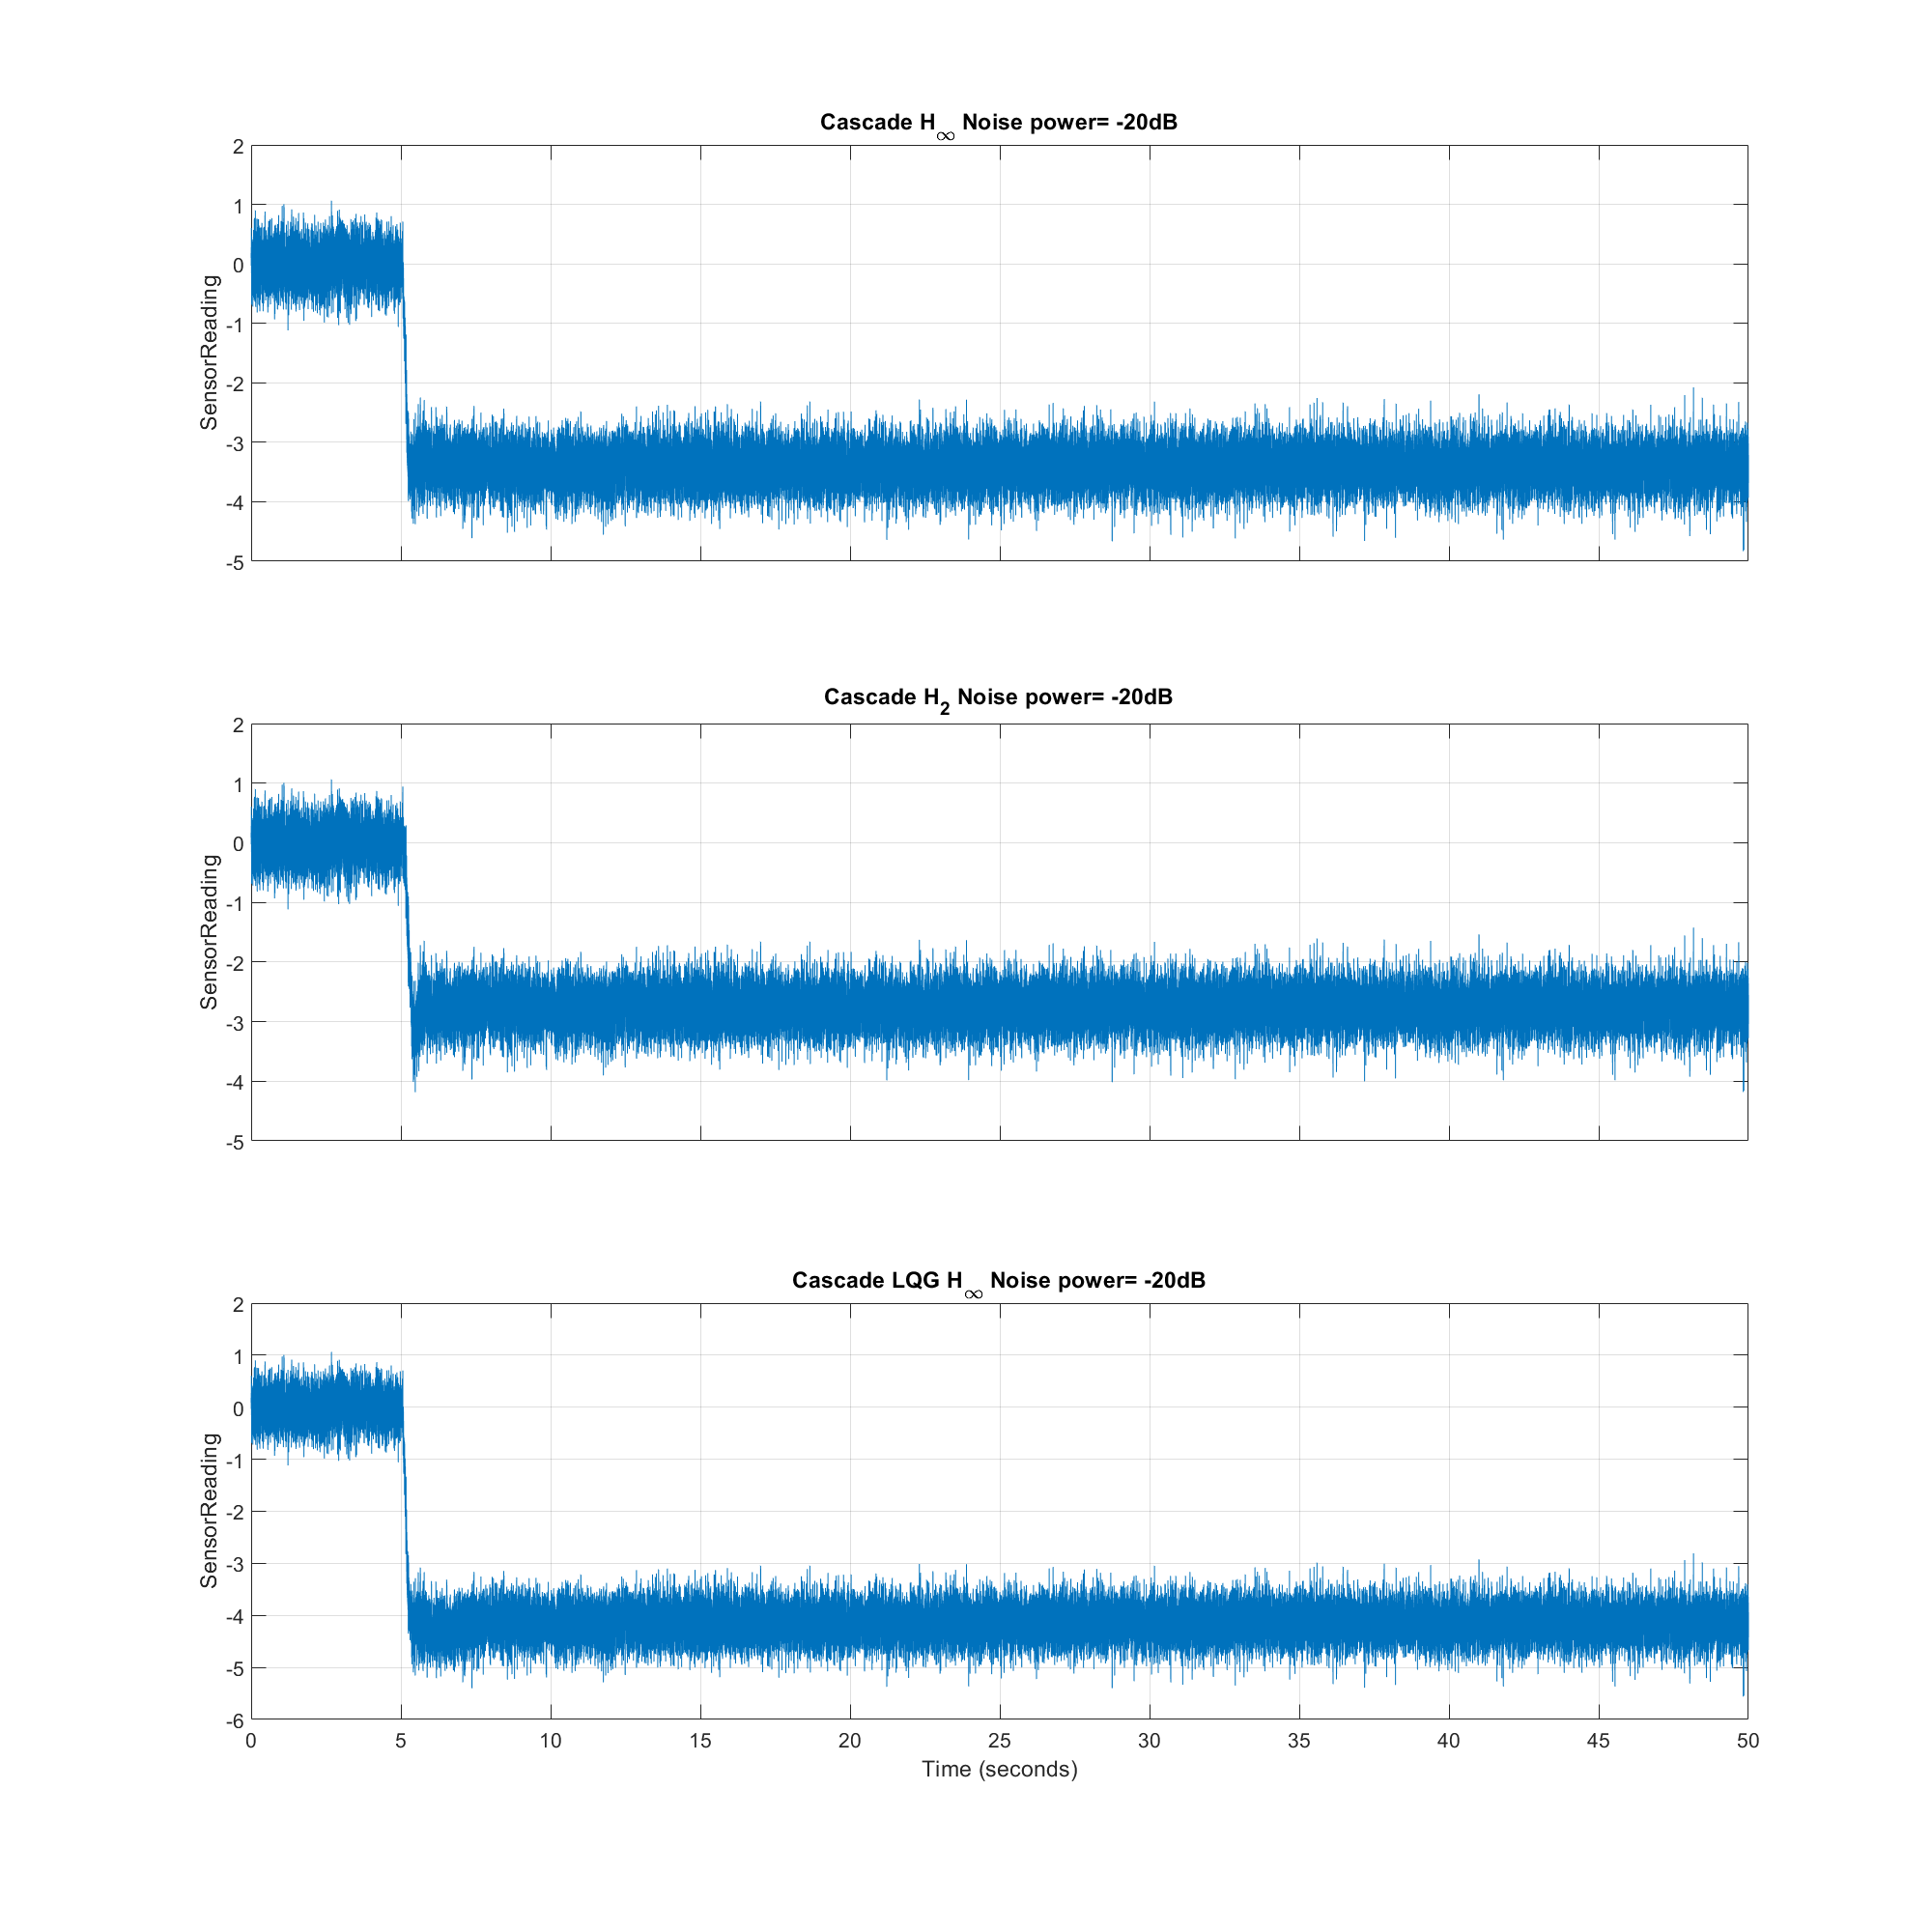

runs = [2,3,4];
fid(8)=plot_map(results(1).Use_Noise,'keys',keys_names(runs),'title',strcat(titles_names(runs),' Noise power= -20dB'),'FigureTitle','ppt_plot_stepResponce_Cascade');

## Print Results

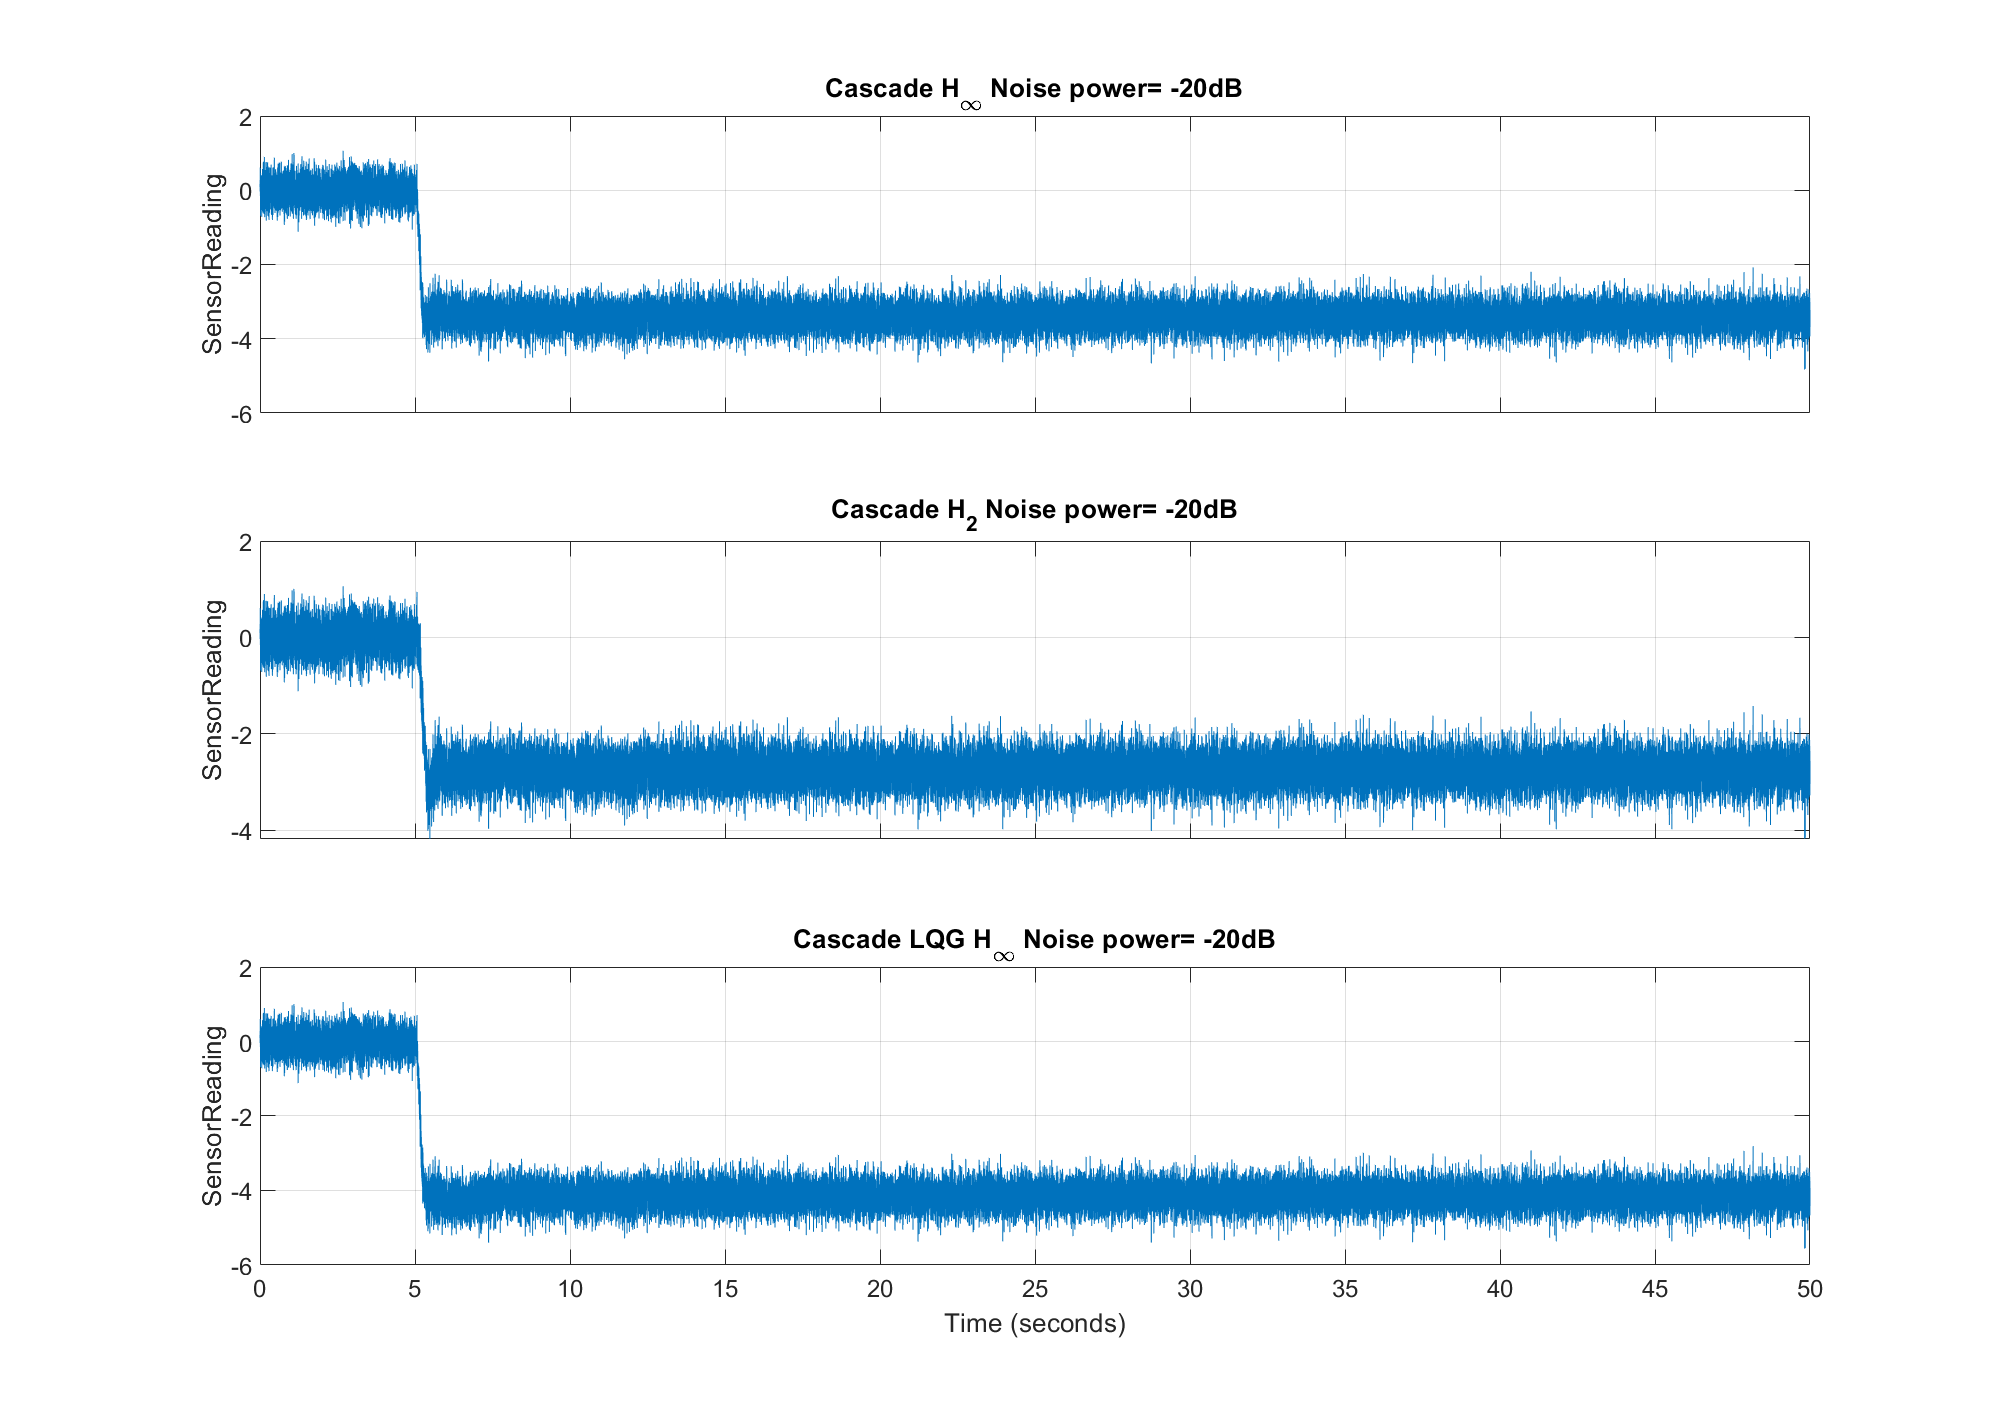

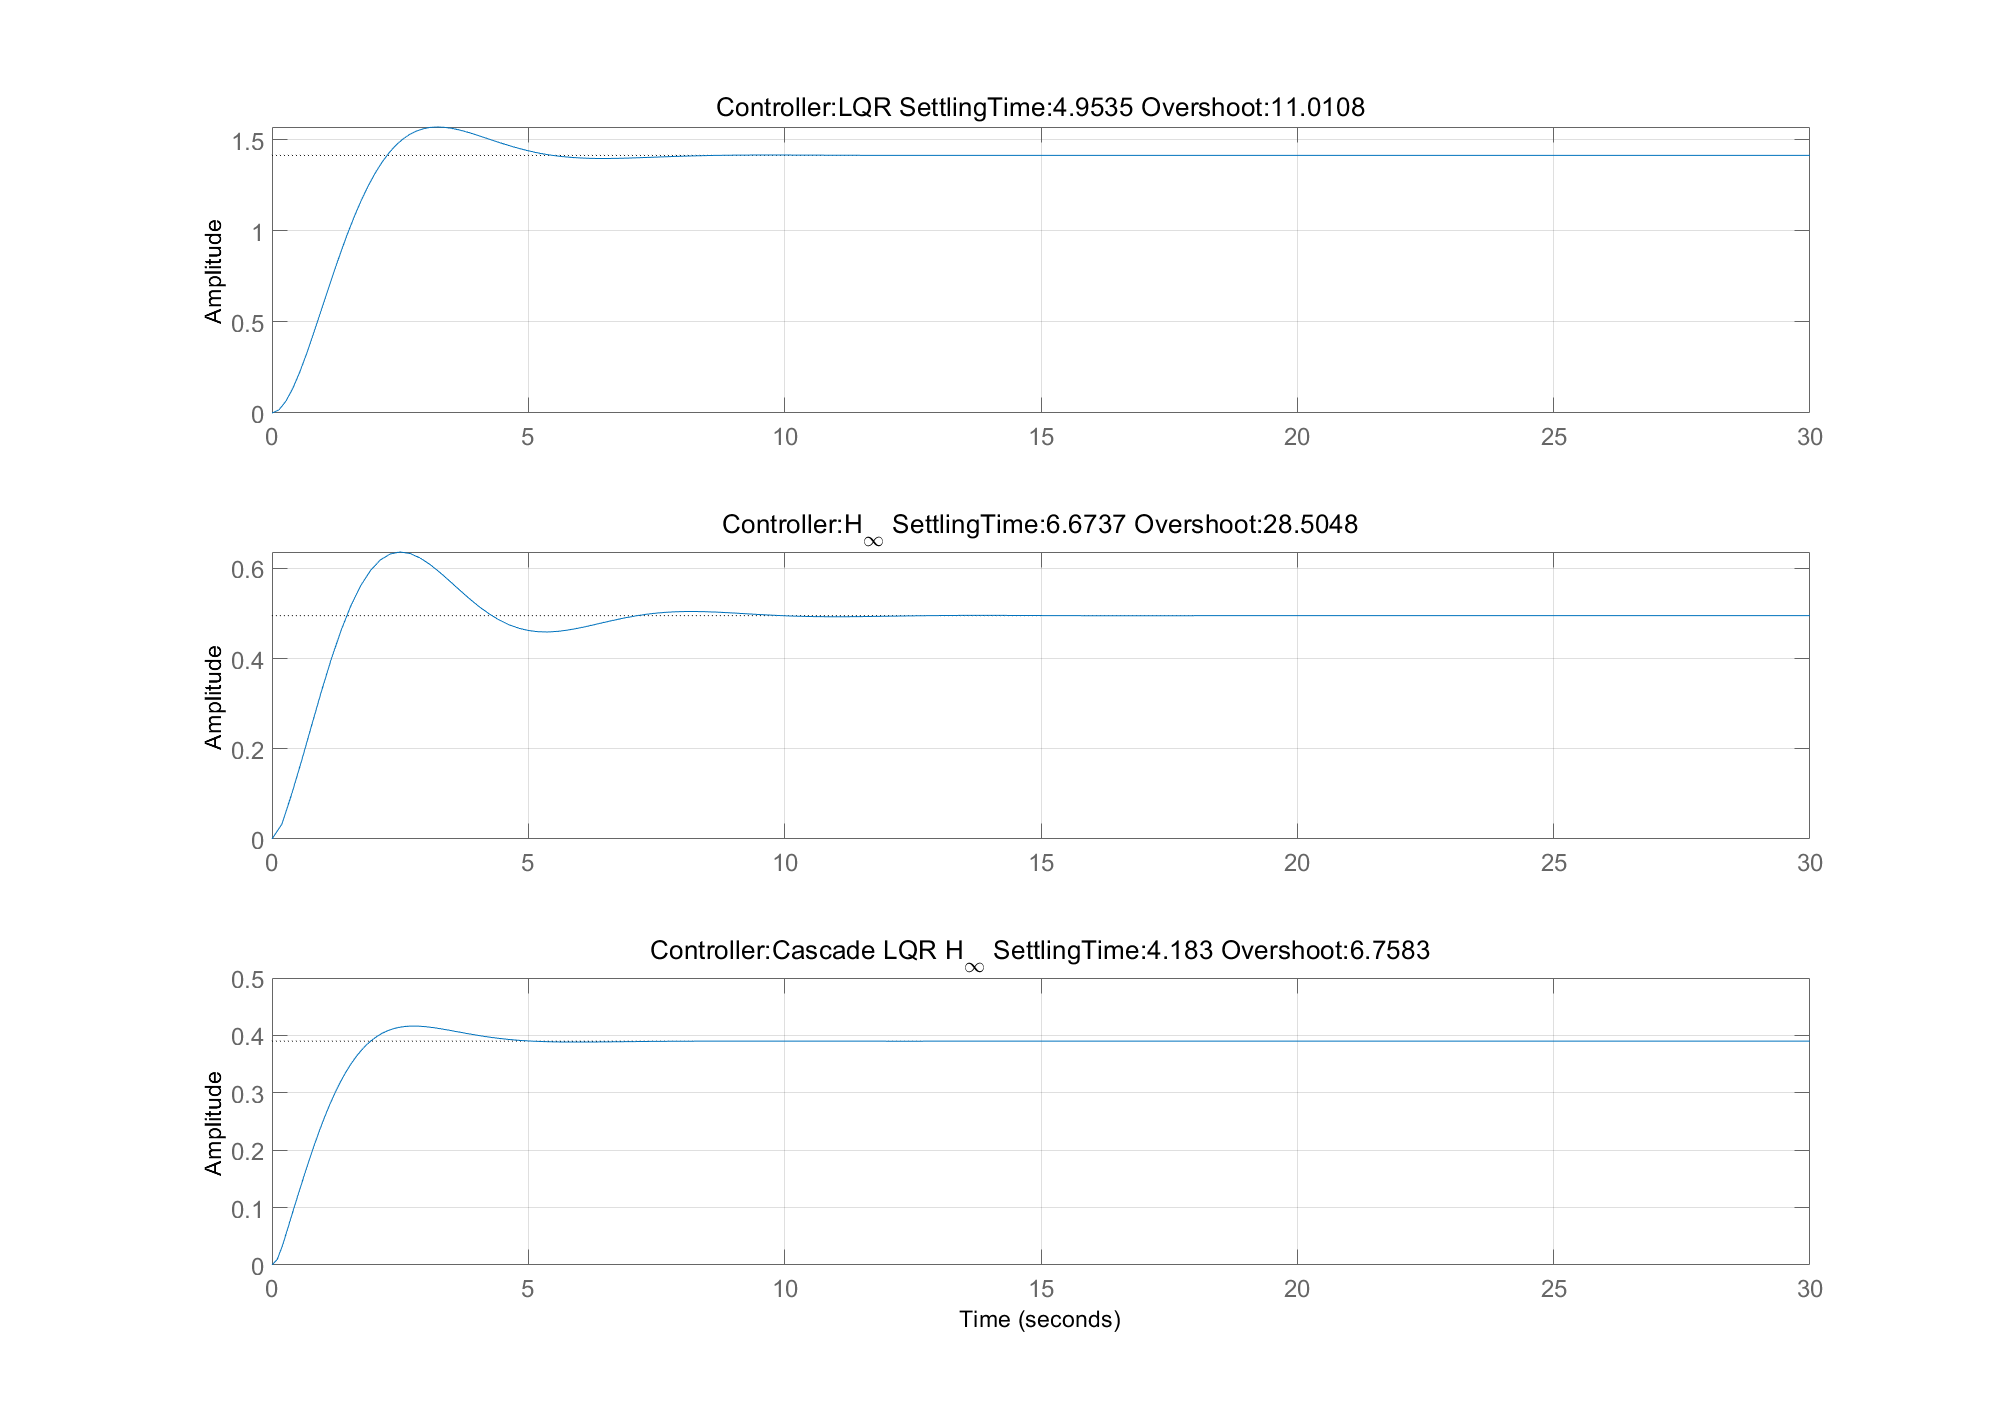

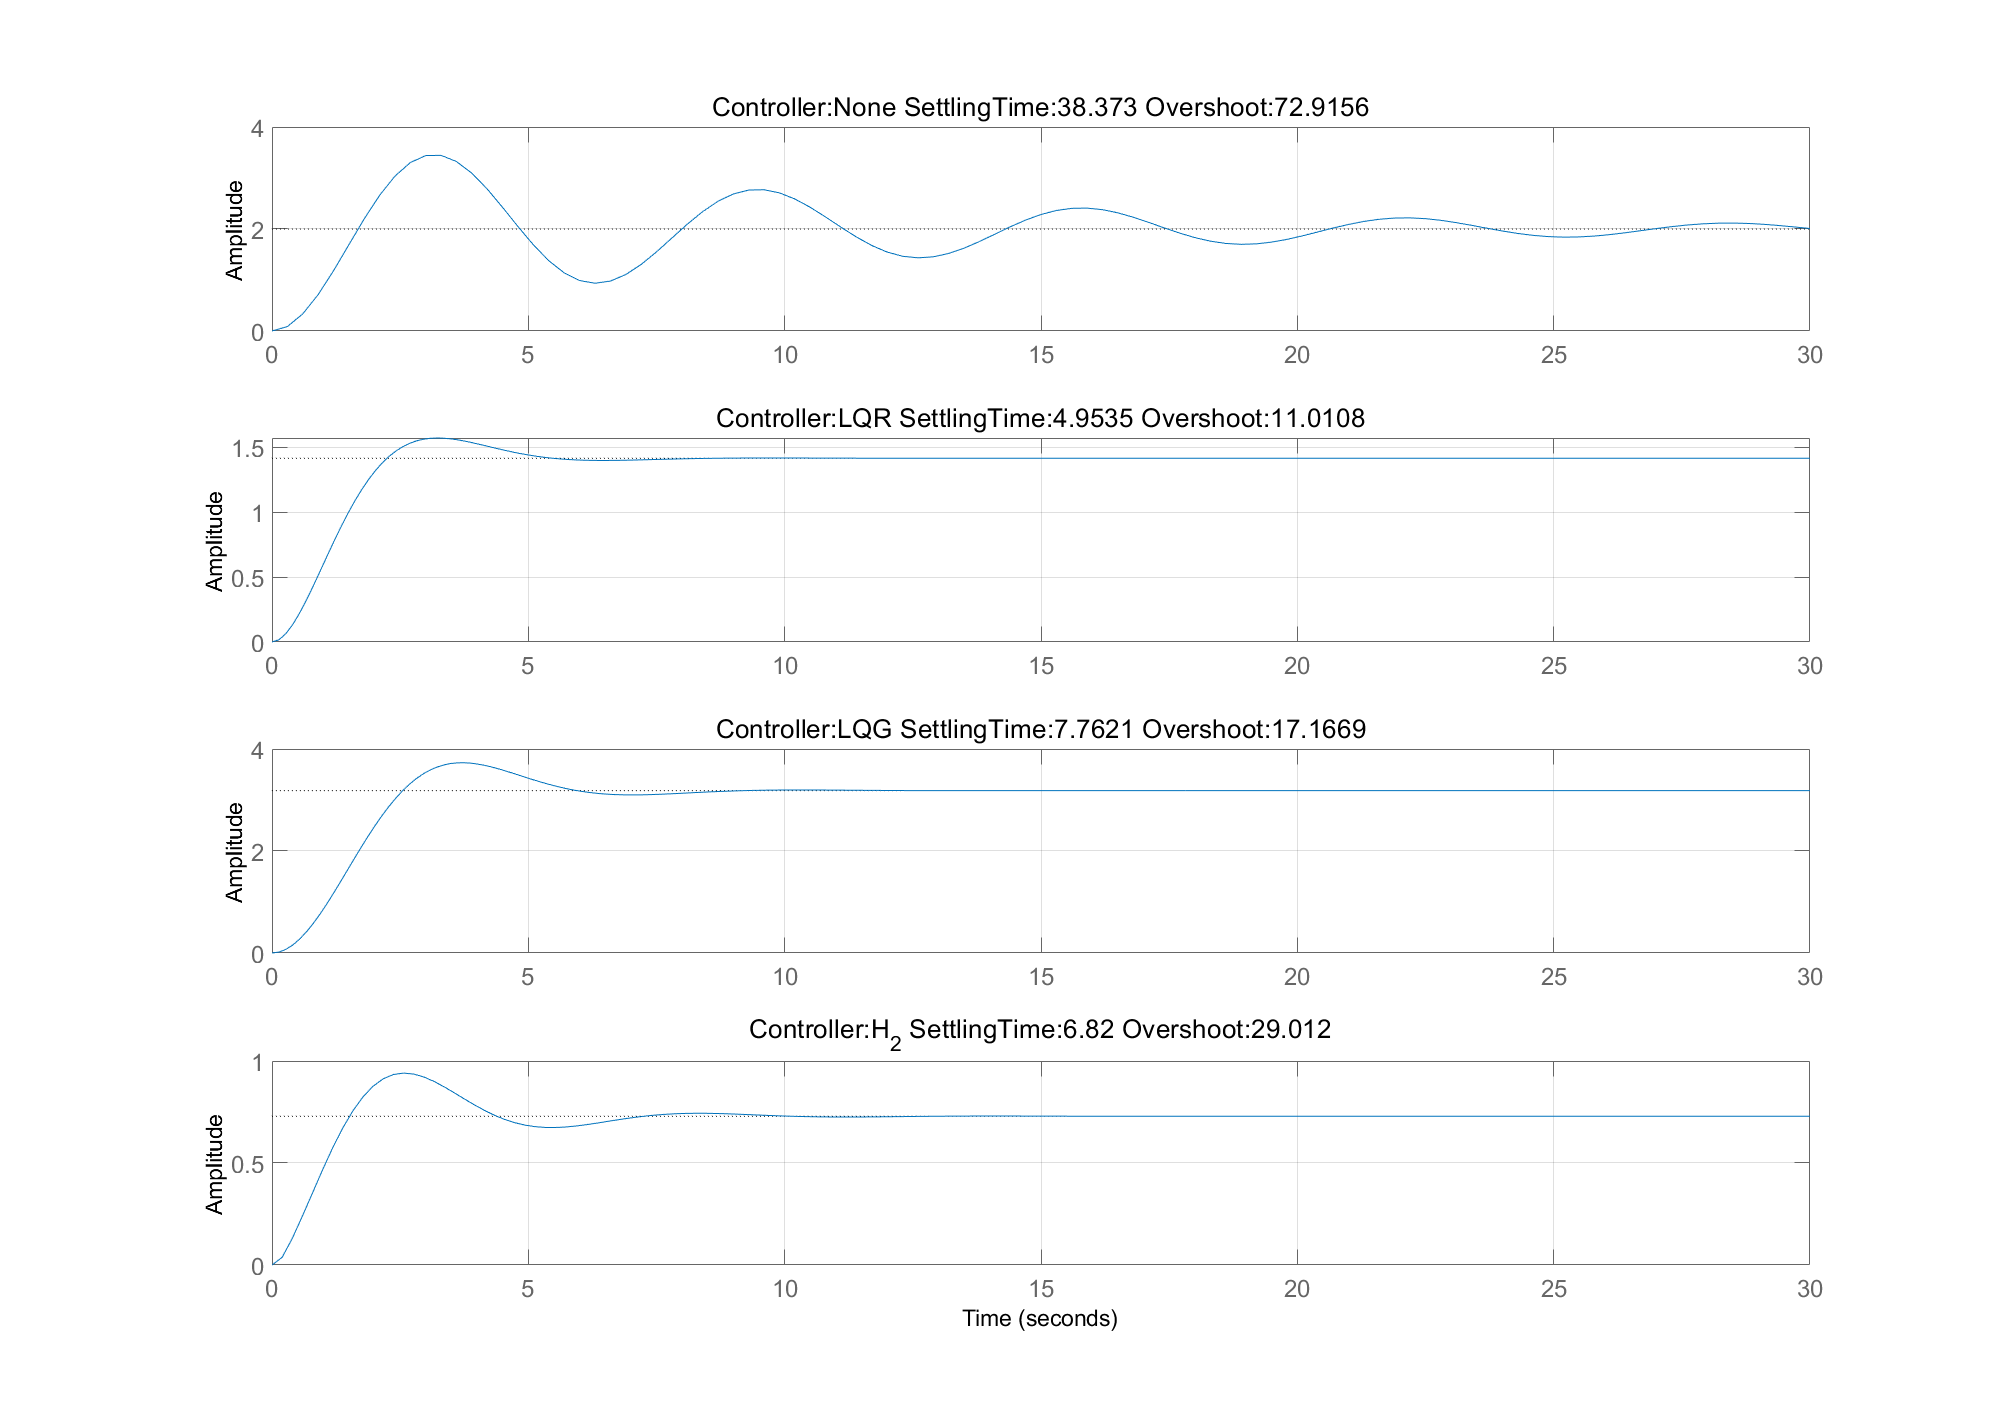

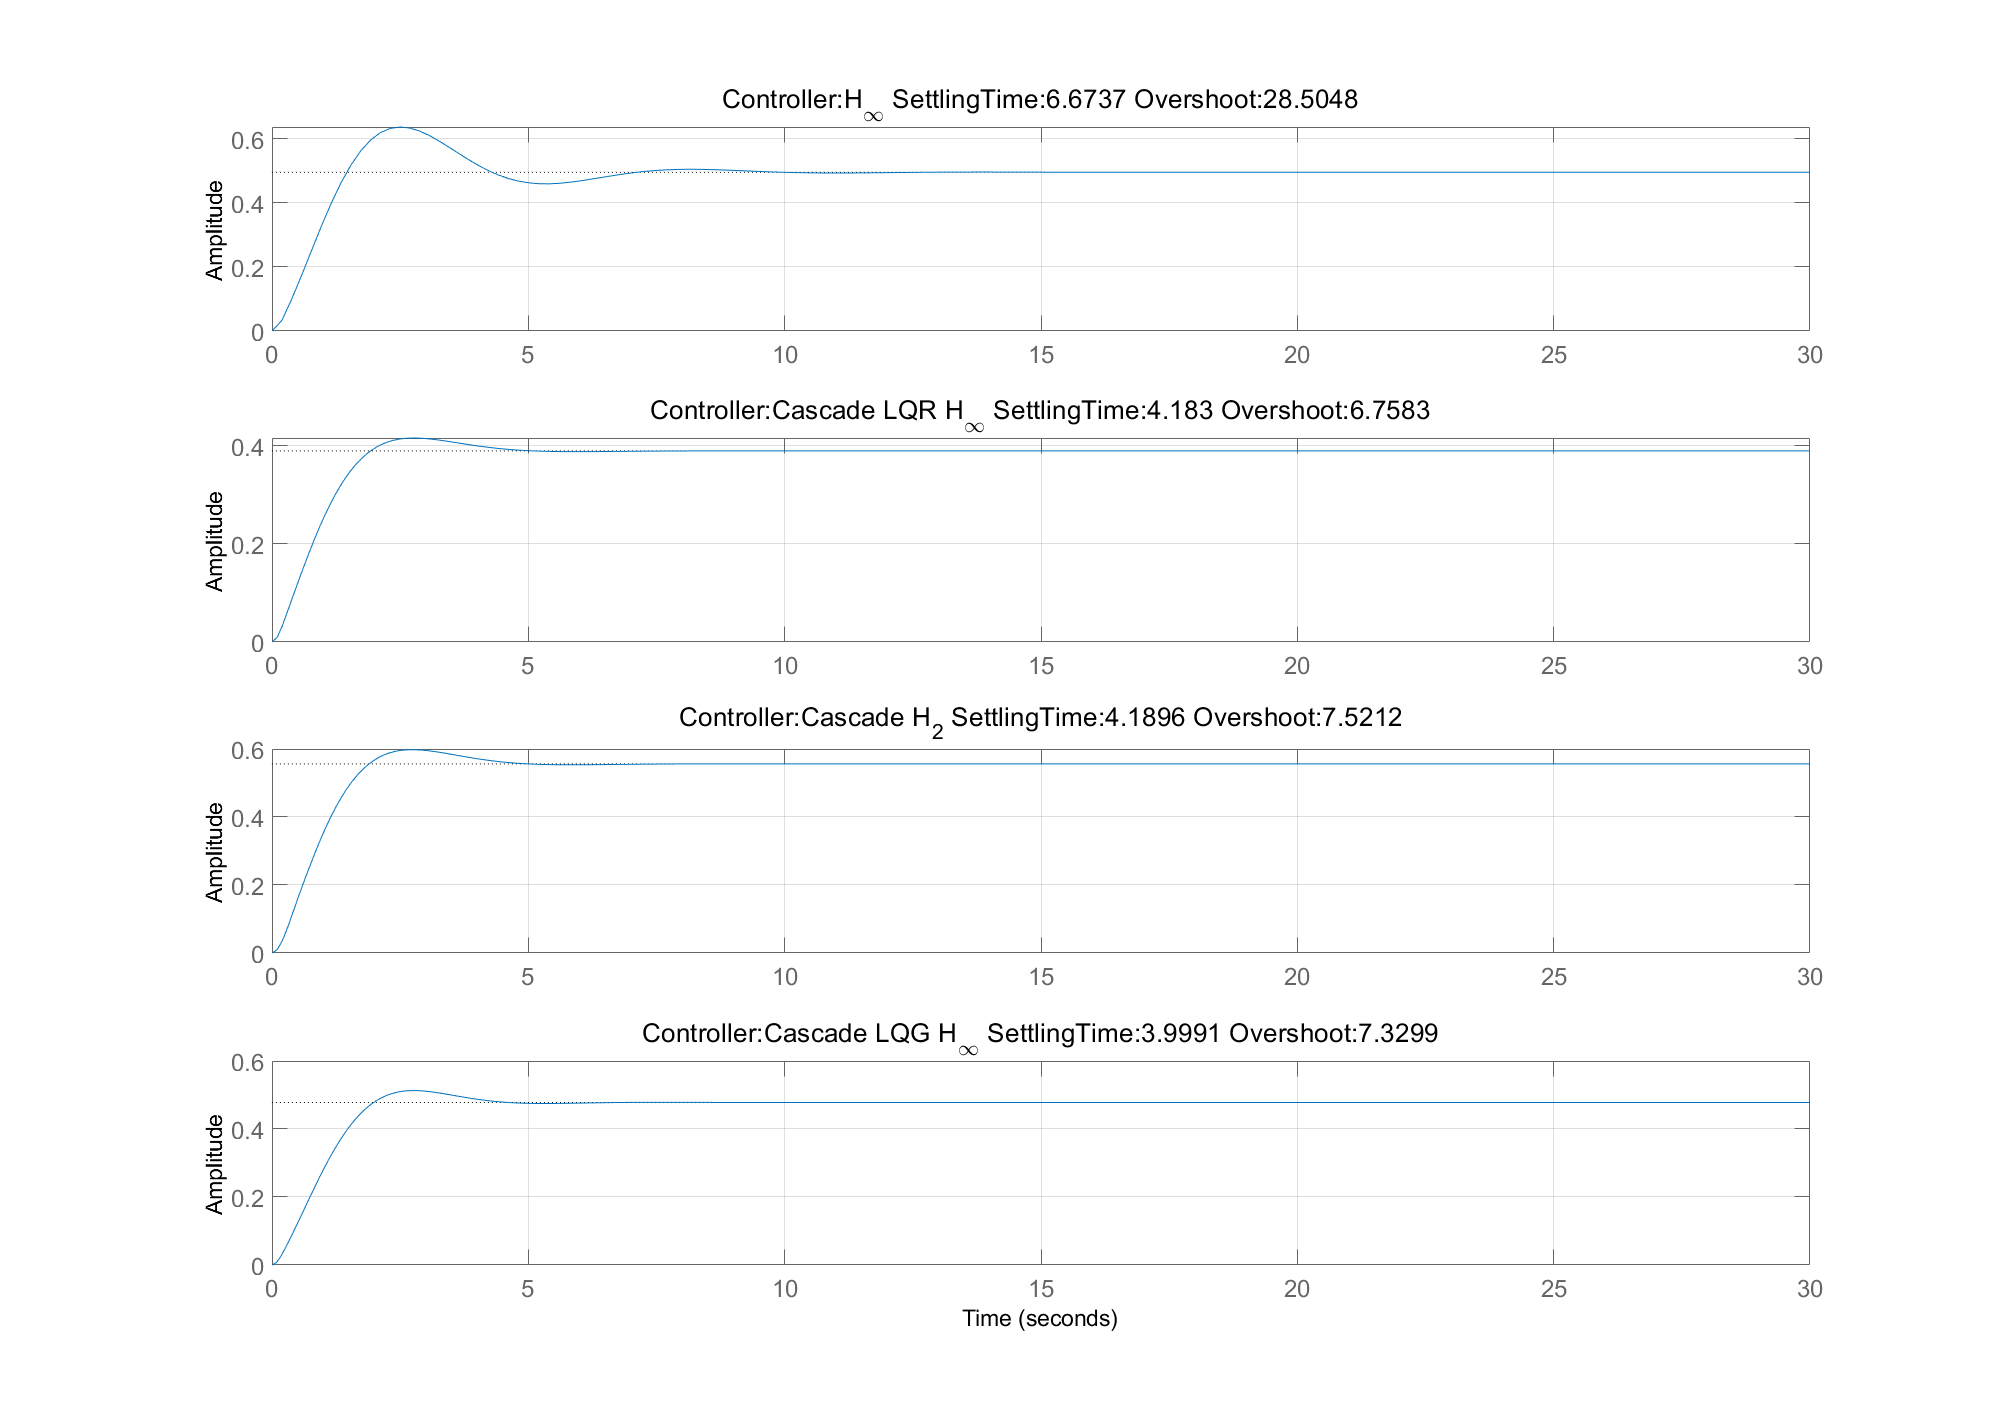

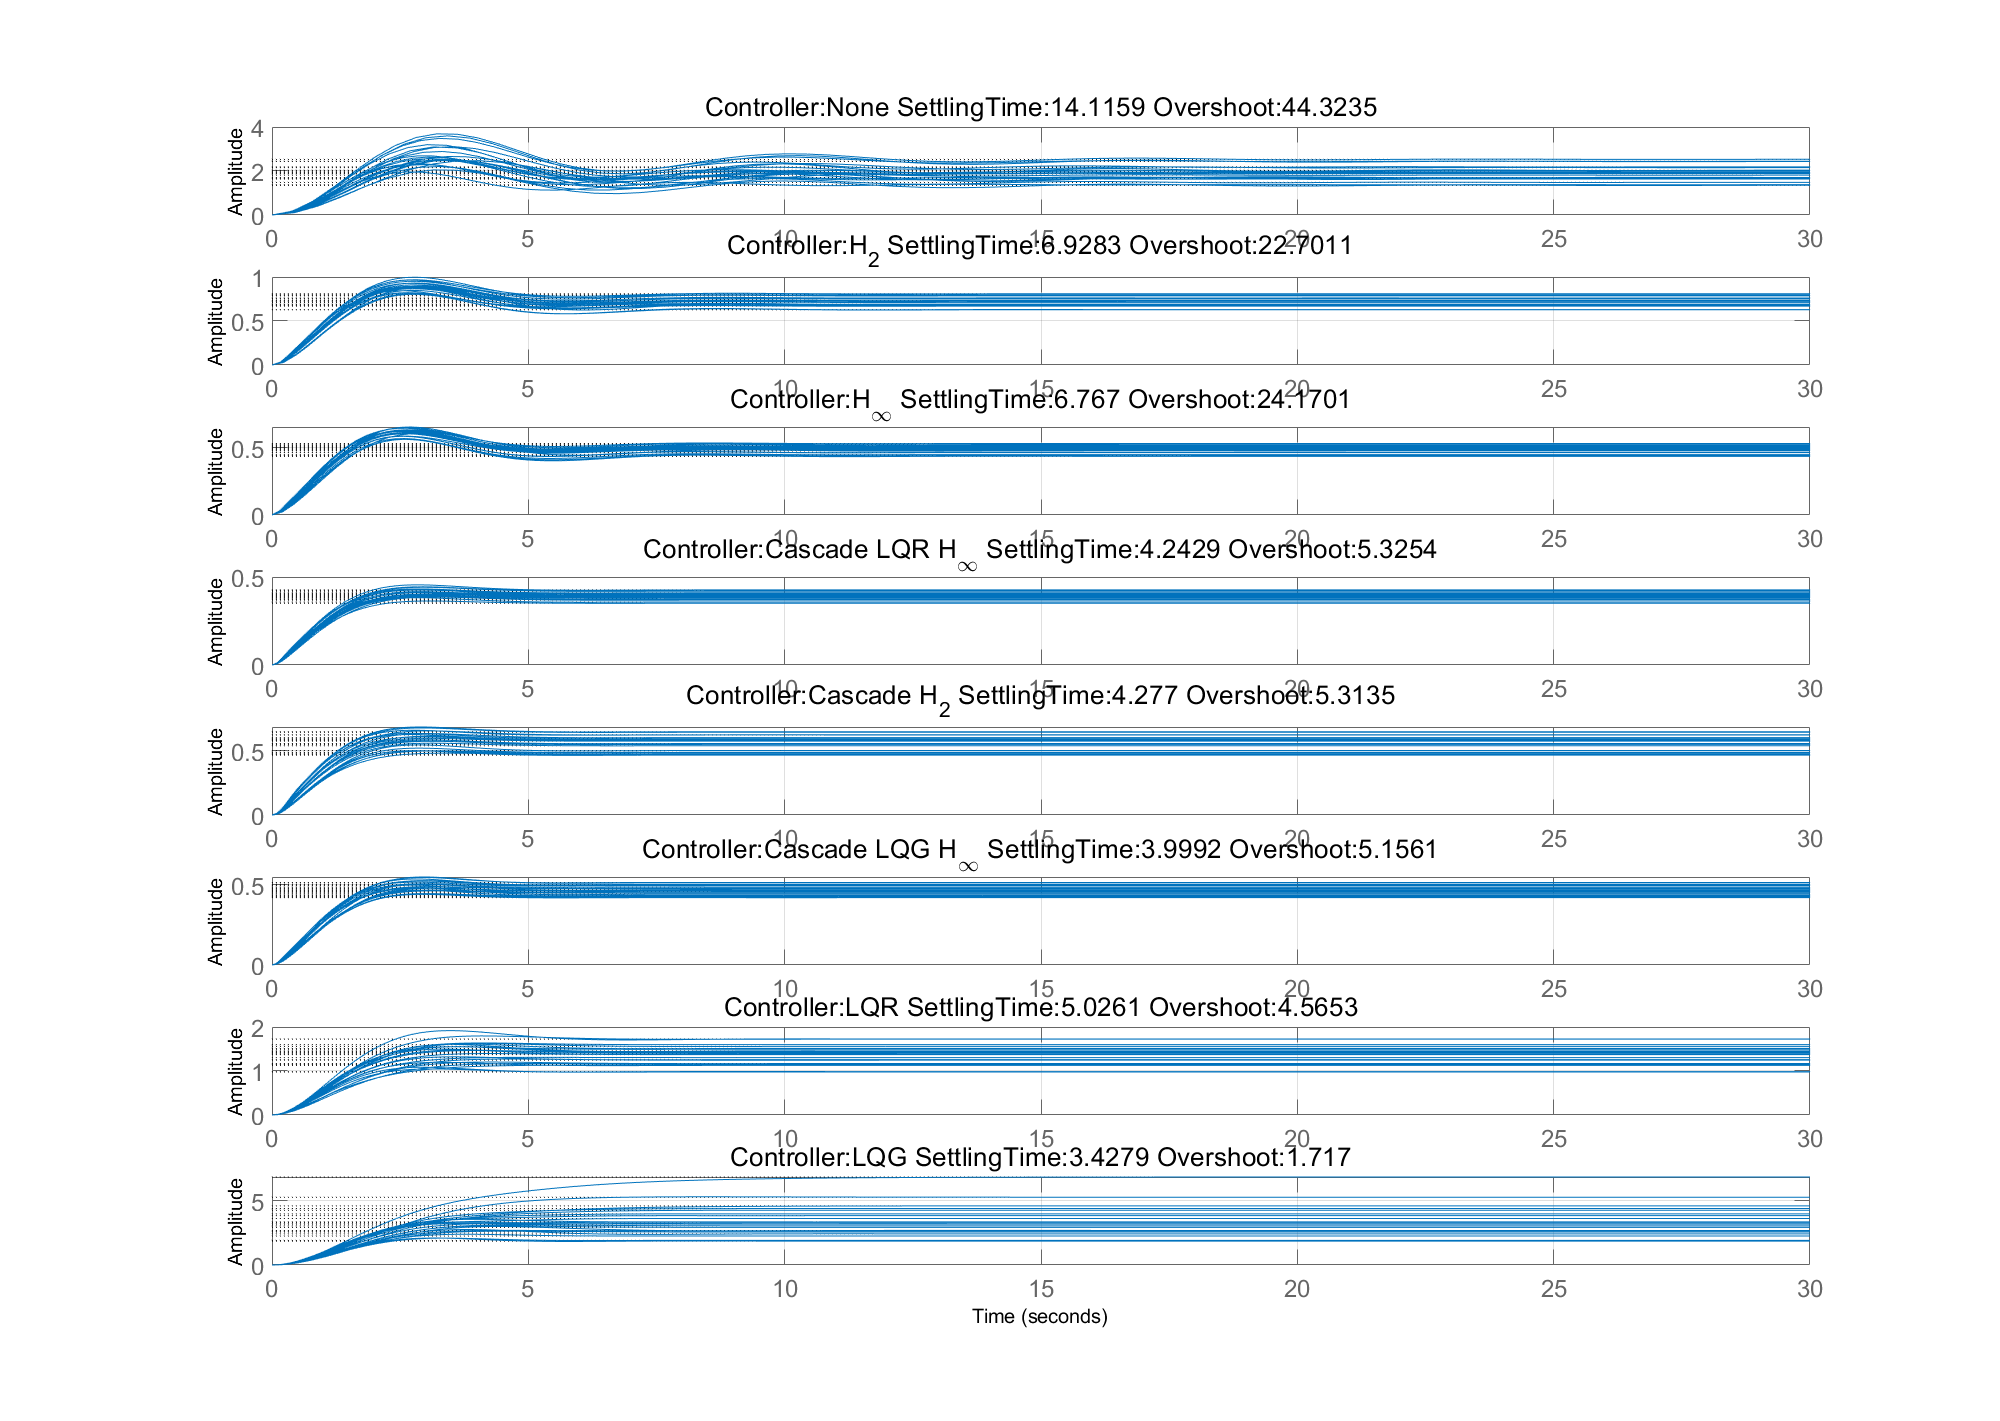

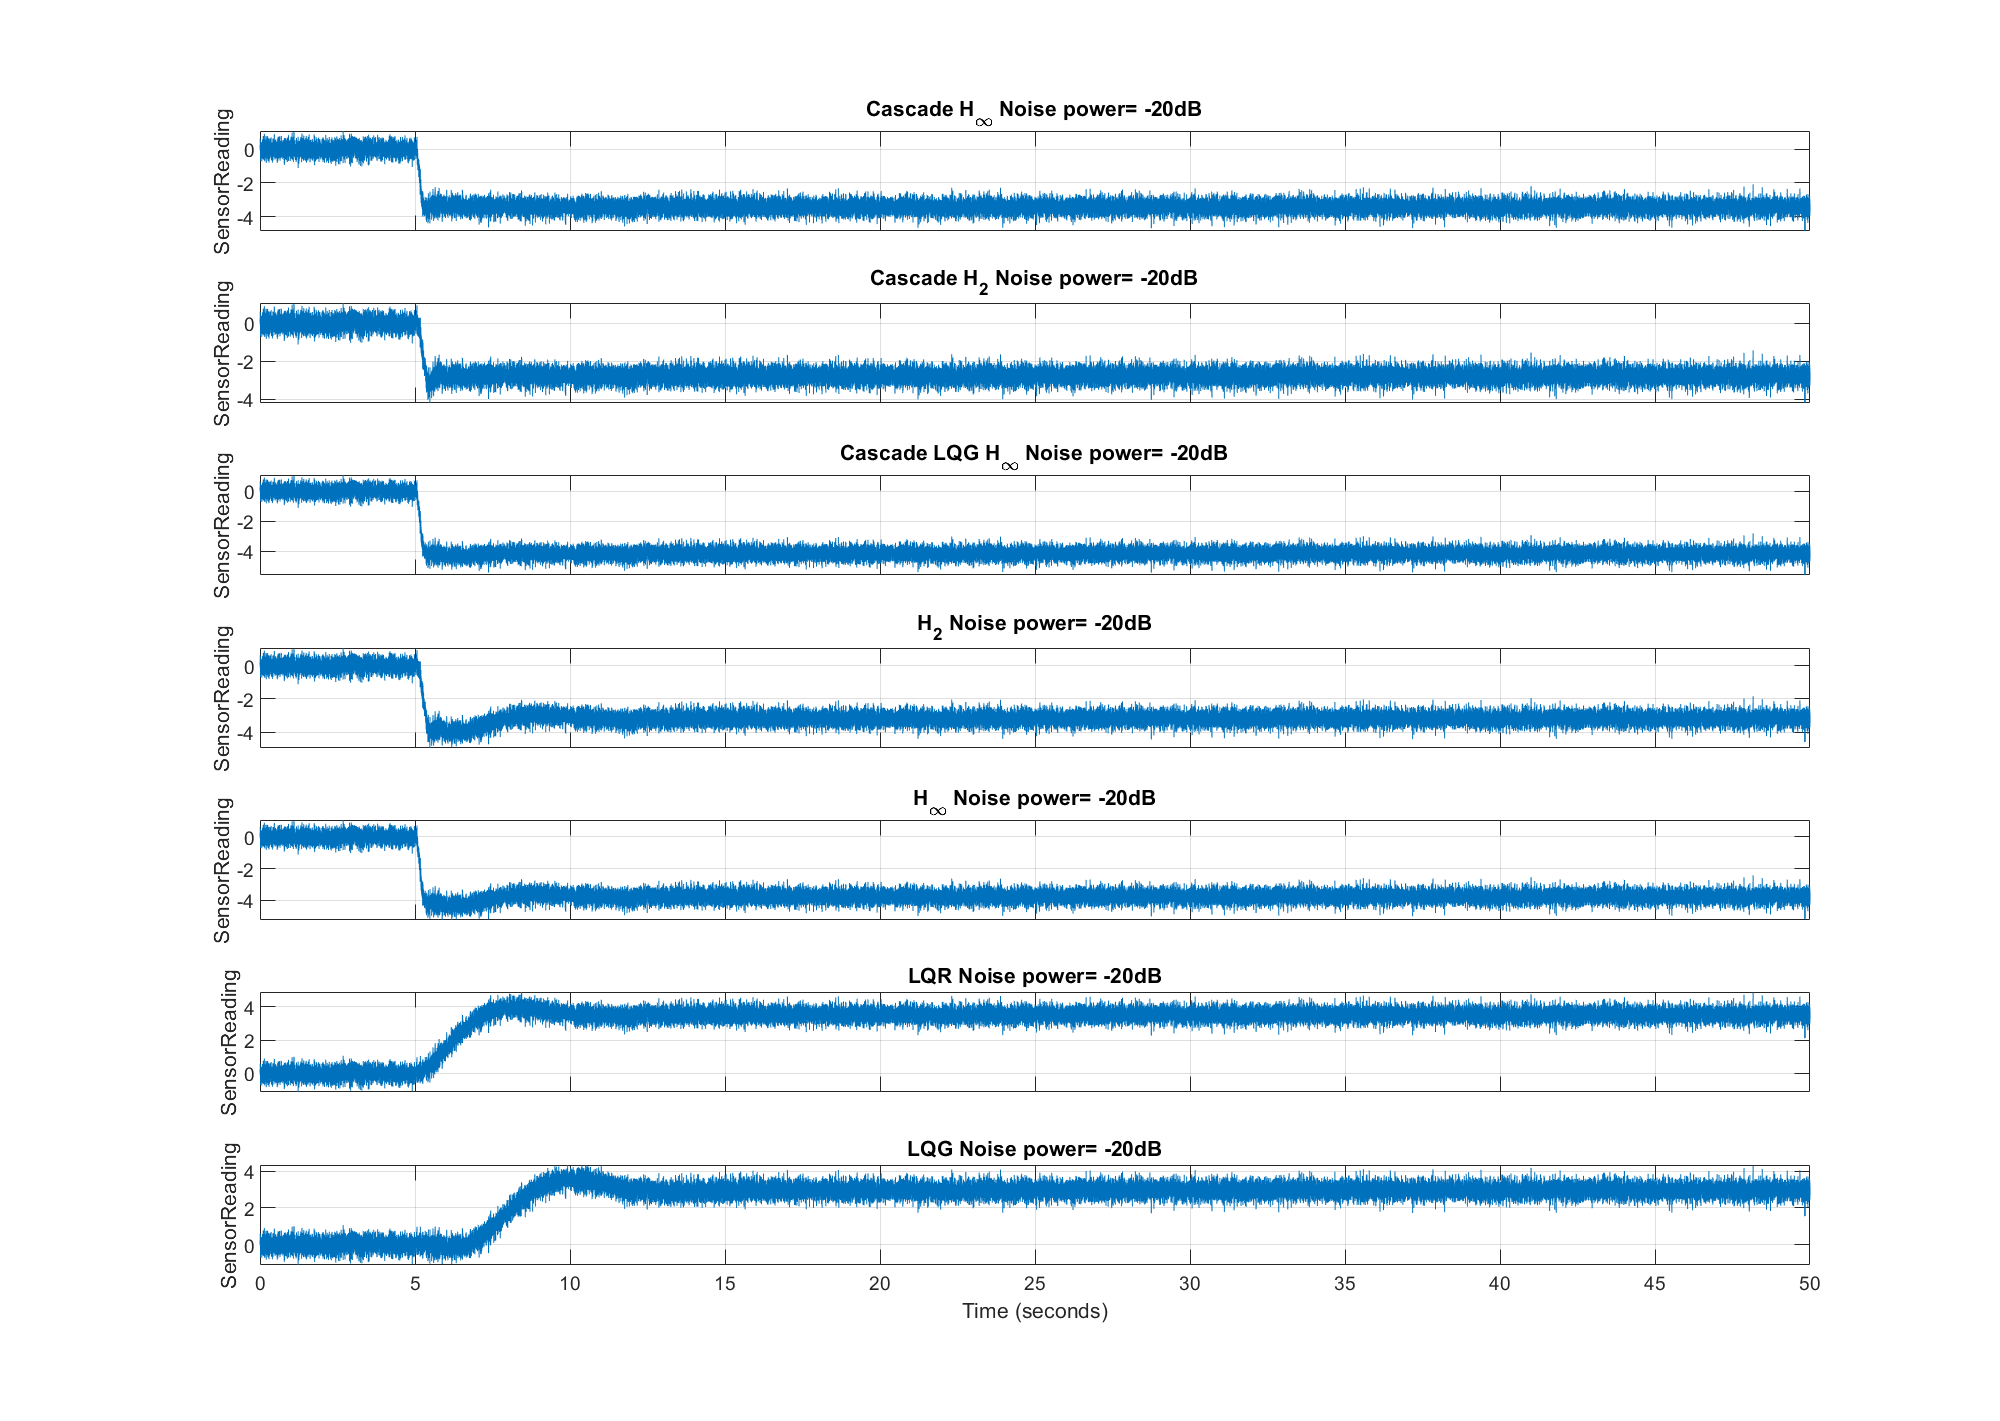

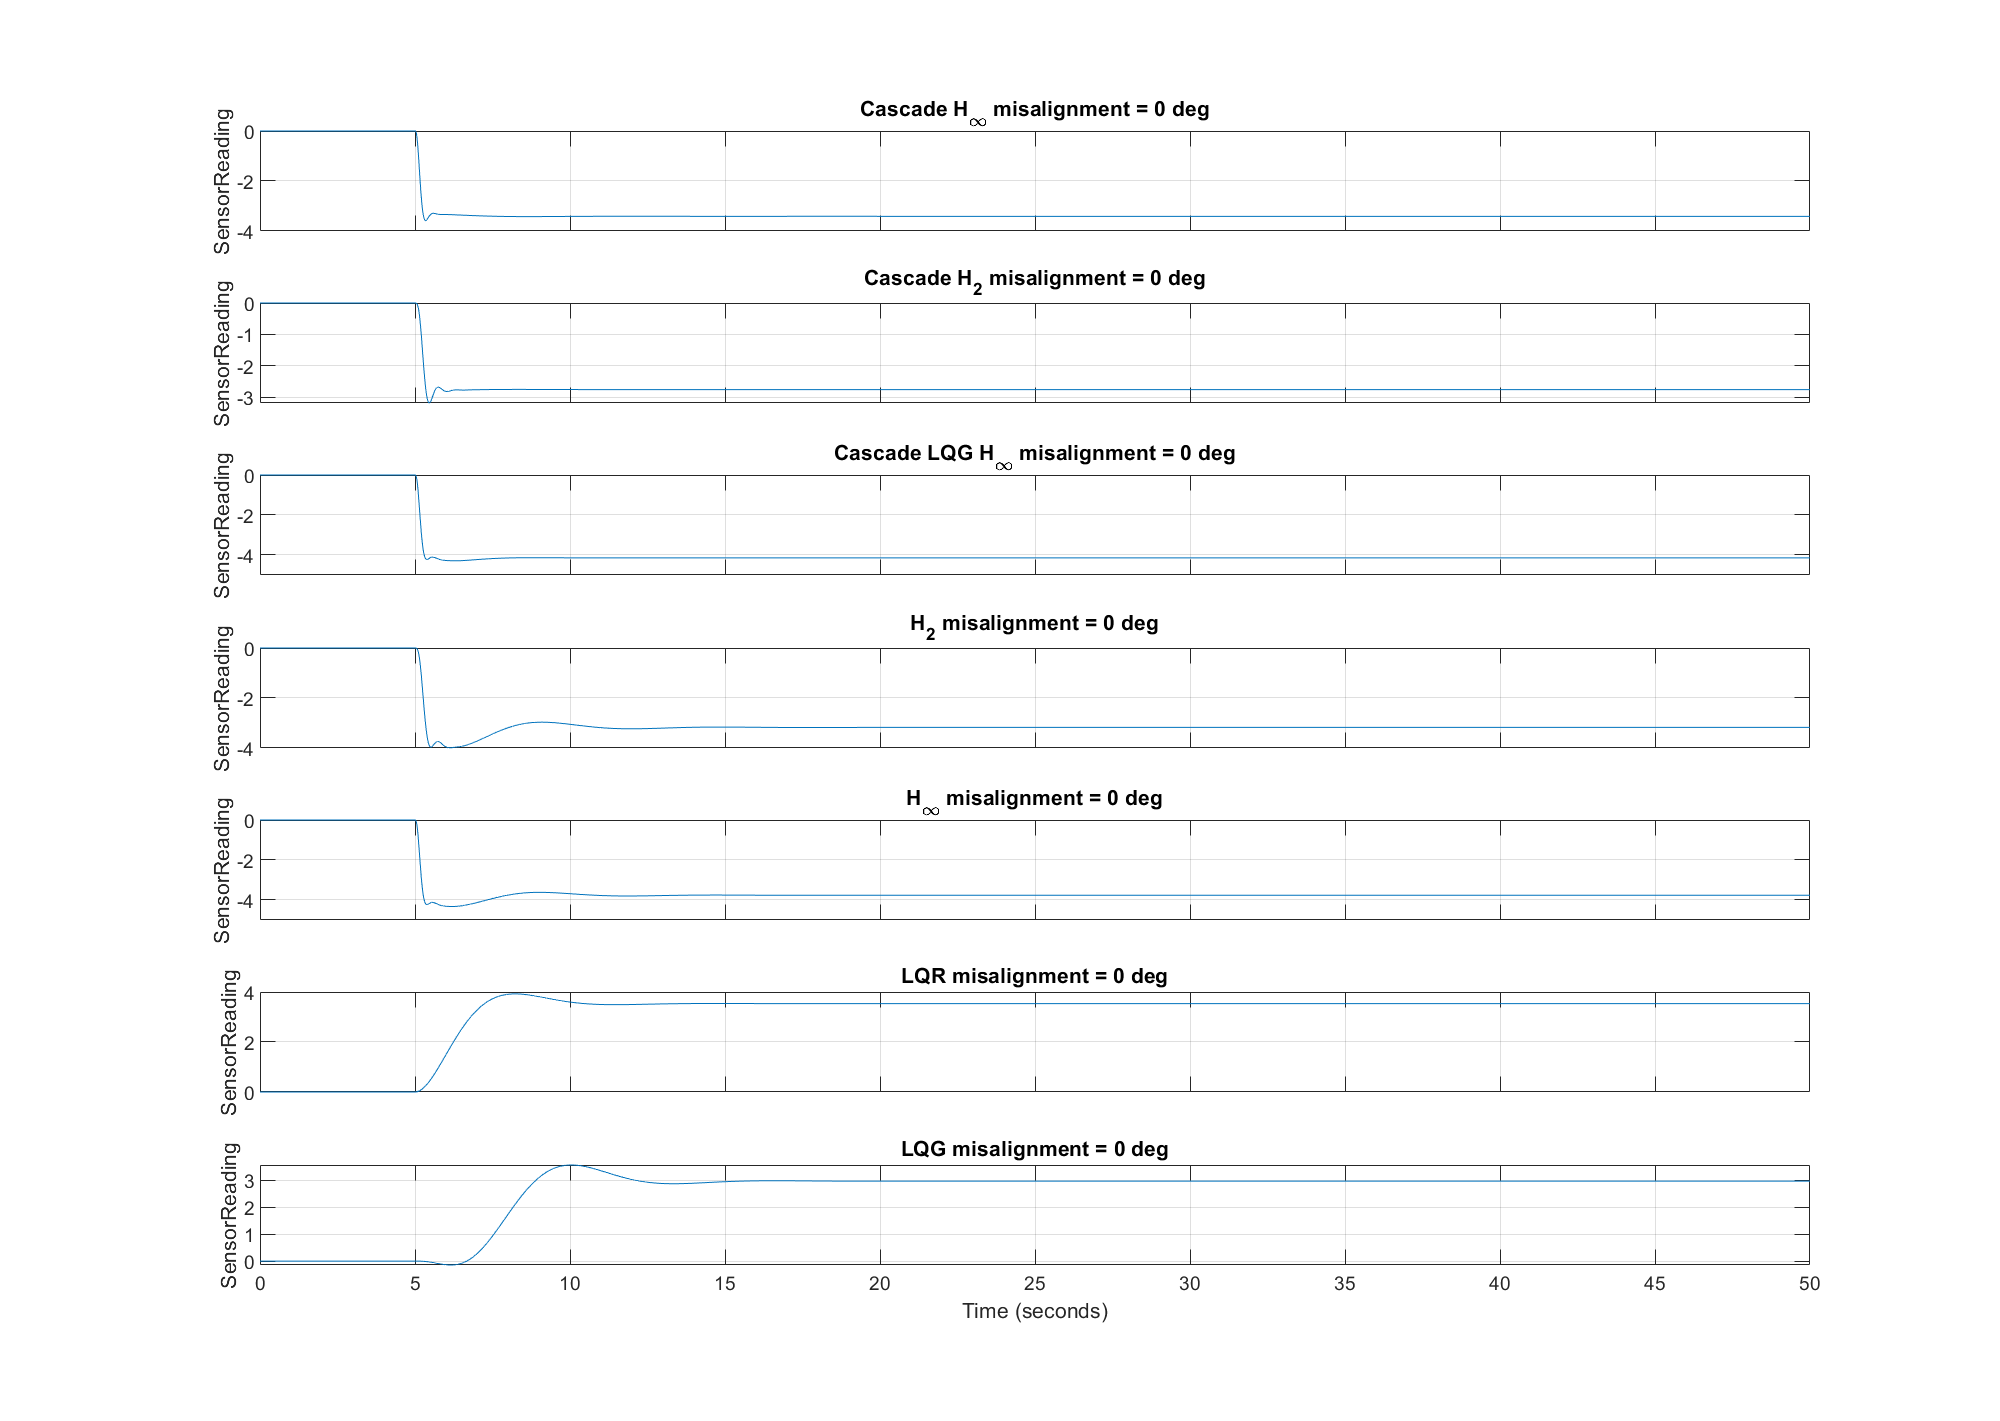

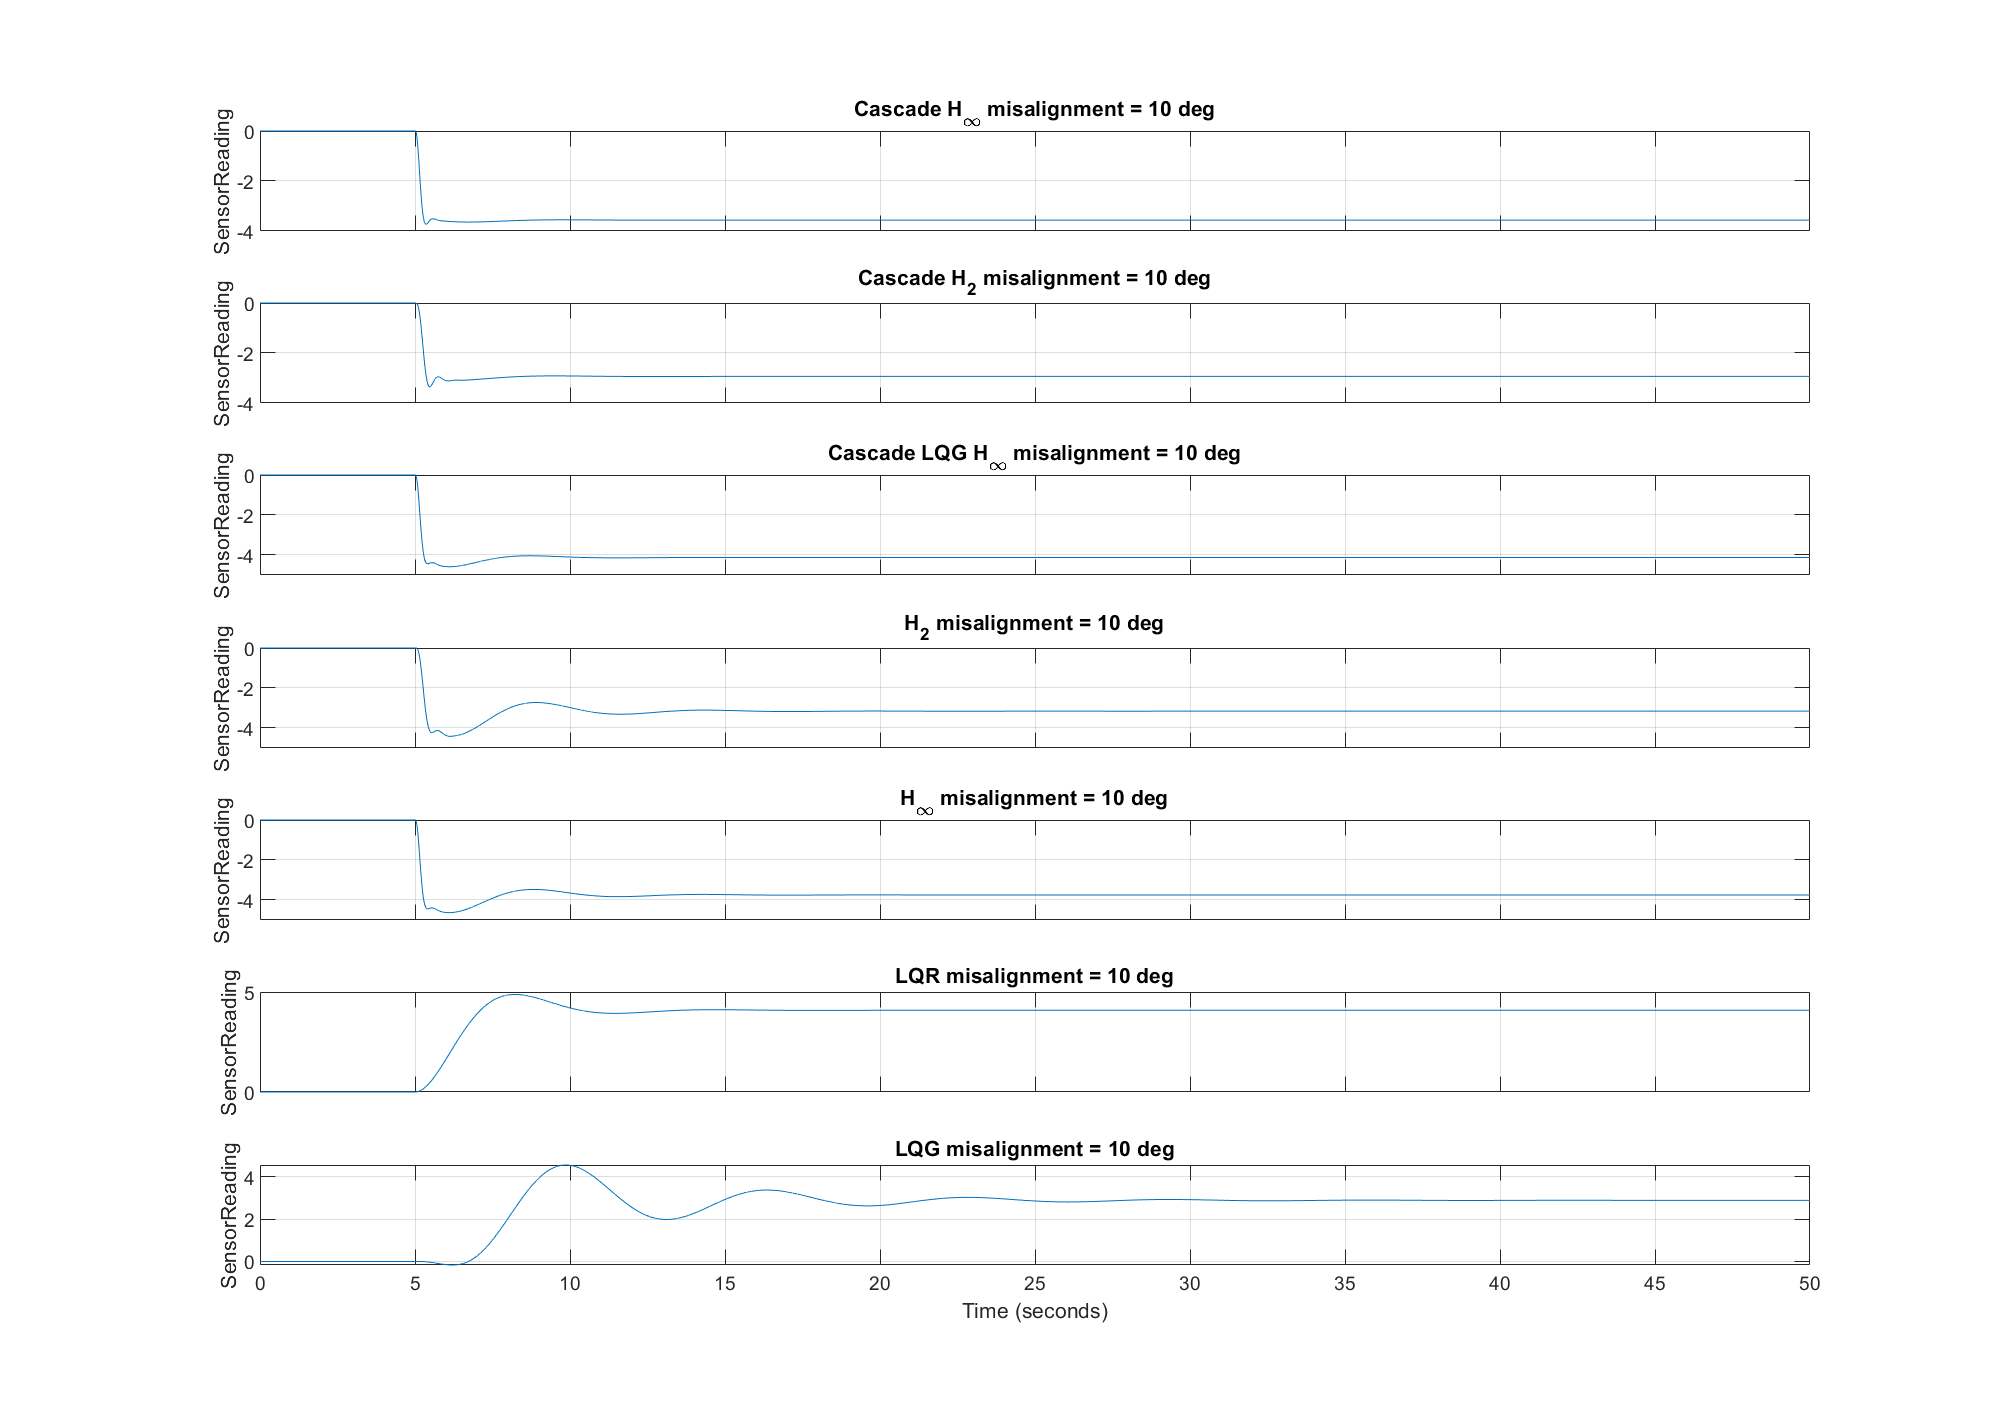

set(findall(gcf,'-property','FontSize'),'FontSize',18)
for itr = 1:numel(fid)
    print(fid(itr),[fig_folder,filesep,fid(itr).Name],'-dpdf');
    print(fid(itr),[fig_folder,filesep,fid(itr).Name],'-dpng');
end